# Respiroception methods paper analysis

Notebook to reproduce analysis and figures for the Respiroception methods paper. 

### Prepare configuration

%% Define plotting variables
saveplots   = 0;
lineWidth   = 1;
fontName    = 'Helvetica';
fontSize    = 18;%24;
scatterMarkerSize   = 40;

try
    % get nice colours from colorbrewer
    % (https://uk.mathworks.com/matlabcentral/fileexchange/34087-cbrewer---colorbrewer-schemes-for-matlab)
    [cb] = cbrewer('qual', 'Set2', 12, 'pchip');
    [sq] = cbrewer('seq', 'BuGn', 8, 'pchip');
catch
    % if you don't have colorbrewer, accept these far more boring colours
    cb = [0.5 0.8 0.9; 1 1 0.7; 0.7 0.8 0.9; 0.8 0.5 0.4; 0.5 0.7 0.8; 1 0.8 0.5; 0.7 1 0.4; 1 0.7 1; 0.6 0.6 0.6; 0.7 0.5 0.7; 0.8 0.9 0.8; 1 1 0.4];
end
cl(1,:) = cb(1,:);        % teal
cl(2,:) = cb(3,:);        % orange
cl(3,:) = cb(12,:);       % gray

% % coordinates for figures
fig_position1 = [200,200,743,346];
fig_position2 = [200,200,346,346];

addpath(genpath('helperFunctions'))                                  % add the helpers & HMeta-d toolbox to path

## FIGURE 2

### Load the trial-level data

%% Select a file & load
fPath           = '../../data/RRST_TrialLevelData_12-Apr-2021_14-49.csv';
data            = readtable(fPath);

% Get out some variables
data            = sortrows(data,1);         % order rows by subject ID
idx1            = data.staircase == 1;      % psi
idx2            = data.staircase == 2;      % quest
idx3            = data.response == 1;       % correct
idx4            = data.response == 0;       % incorrect
psidata         = data(idx1,:);
questdata       = data(idx2,:);
corr            = data(idx3,:);
incorr          = data(idx4,:);
idx5            = psidata.response == 1;    % Psi correct
idx6            = psidata.response == 0;    % Psi incorrect
idx7            = questdata.response == 1;    % Quest correct
idx8            = questdata.response == 0;    % Quest correct
psicorr         = psidata(idx5,:);
psiincorr       = psidata(idx6,:);
questcorr       = questdata(idx7,:);
questincorr     = questdata(idx8,:);
subNo           = unique(data.ID);

% Clean up
clear idx1 idx2 idx3 idx4 idx5 idx6 idx7 idx8

### Loop over Psi and QUEST staircase methods

Plot stimulus traces, psychometric functions, RT x accuracy, confidence x accuracy and accuracy over subjects.

%% Figure with stim traces, pmf, RT & confidence x accuracy, and accuracy x subject
for procedure = 1:2         % Plot both psi and quest
 
    %% Set up figure
    figure('Position', fig_position1);
    set(gcf,'color','w');
    

Get the data for this method.

    if procedure == 1                   % Psi
        data    = psidata;
        %         sgt = sgtitle(['Psi']);
    else                                % Quest
        data    = questdata;
        %         sgt = sgtitle(['QUEST']);
    end
    sgt.FontSize = fontSize+4;
    spCols = 3;
    spRows = 1;
    

Get the trial number and threshold estimates by trial.

    %% A. Threshold estimate by trial
    
    % Loop over subjects % plot
    allXVals    = nan(length(subNo),100);
    allSEs      = nan(length(subNo),100);
    allStimsQuest = nan(length(subNo),100);
    
    
    for thisSub = 1 : length(subNo)
        thisSubId = subNo(thisSub);
        
        trials      = data(data.ID == thisSubId, 2);
        trials      = trials.trialN;
        xVals       = 1:length(trials);
        
        if procedure == 1           % Psi
            threshEst   = psidata(psidata.ID==thisSubId, :).thresh;
            seThresh    = psidata(psidata.ID==thisSubId, :).slope;
            
            SEhi        = threshEst + seThresh;
            SElo        = threshEst - seThresh;
            
            % Plot line, threhsold estimate
            plot(xVals,threshEst,'Color',cl(3,:),'LineWidth',lineWidth); hold on
            
            
        else                        % Quest
            trialStims  = questdata(questdata.ID==thisSubId, :).stimLevel;
            threshEst   = questdata(questdata.ID==thisSubId, :).thresh;
            % Calculate difference to threshold estimate for each trial
            estDifference   = abs(trialStims - threshEst);
            seThresh    = estDifference;
            allStimsQuest(thisSub, 1:size(trialStims',2))     = trialStims';
            
            % Plot line, presented stimuli
            plot(xVals,trialStims,'Color',cl(3,:),'LineWidth',lineWidth); hold on
        end
        
        
        allXVals(thisSub, 1:size(threshEst',2))     = threshEst';
        allSEs(thisSub, 1:size(seThresh',2))        = seThresh';
        
    end
    

Add the mean stimulus level and 95% confidence intervals.

    if procedure == 1
        meanStim    = nanmean(allXVals);
        lower   = allXVals - allSEs;
        upper   = allXVals + allSEs;
        
        SEM     = nanstd(allXVals)/sqrt(size(allXVals,2));                % Standard Error of mean
        N = size(allXVals,1);
        
    elseif procedure == 2
        allXVals = allXVals(:,all(~isnan(allXVals))); % remove NaN cols
        meanThresh    = nanmean(allXVals);
        allSEs = allSEs(:,all(~isnan(allSEs)));
        allStimsQuest = allStimsQuest(:,all(~isnan(allStimsQuest)));
        
        meanStim = nanmean(allStimsQuest);
        lower   = allStimsQuest - allSEs;
        upper   = allStimsQuest + allSEs;
        
        SEM     = nanstd(allStimsQuest)/sqrt(size(allStimsQuest,2));                % Standard Error of mean
        N       = size(allStimsQuest,1);
        
        plot(xVals,meanThresh,'Color',cl(1,:),'linewidth',lineWidth*2)
    end
    
    % Add mean stim level x trial, & CIs
    lower   = nanmean(lower);
    upper   = nanmean(upper);
    
    
    % Calculate 95% CIs
    CI95    = tinv([0.025 0.975], N-1);       	% Calculate 95% Probability Intervals Of t-Distribution
    yCI95   = bsxfun(@times, SEM, CI95(:));   	% Calculate 95% Confidence Intervals Of All Experiments At Each Value Of ?x?
    lower   = meanStim + yCI95(1,:);
    upper   = meanStim + yCI95(2,:);
    
    ciplot(lower,upper,xVals,cl(3,:));         % Plot SEM as filled area
    plot(xVals,meanStim,'Color',cl(1,:),'linewidth',lineWidth*4)
    

Finish up the figure; add axis labels, edit axes. 

    % Add axis labels
    hold on
    if procedure == 1           % Psi
        title('Psi threshold estimate by trial','fontsize',fontSize+2,'FontWeight','Normal');
        procName    = 'Fig1-a_Psi_';
        axis([0 105 3.6 19]);
    else                        % Quest
        title('QUEST presented stimuli by trial','fontsize',fontSize+2,'FontWeight','Normal');
        procName    = 'SuppFig_Quest_';
        axis([0 65 3.4 18.5]);
    end
    
    
    yticks([3.6, 7.2, 10.8, 14.4, 18]);
    yticklabels({'20', '40', '60', '80', '100'});
    xlabel('Trial number');
    ylabel('% Obstruction');
    set(gca,'FontName',fontName,'fontsize',fontSize)
    box off
    

### Plot individua psychometric functions, and mean PMF

Set up figure. 

    %% B. PMF
    figure('Position', fig_position2);
    set(gcf,'color','w');
    
    
    title('PMF fit','fontsize',fontSize+2,'FontWeight','Normal');
    axis([3.4 18 0 1]);
    xticks([3.6, 7.2, 10.8, 14.4, 18]);
    xticklabels({'20', '40', '60', '80', '100'});
    xlabel('% Obstruction');
    ylabel('p(correct response)');
    set(gca,'FontName',fontName,'fontsize',fontSize)
    hold on

Loop over subjects and add PMF traces. 

    % Loop over subjects & plot
    for thisSub = 1 : length(subNo)
        thisSubId = subNo(thisSub);
        
        % Calculate Threshold and Slope
        if procedure == 1   % Psi
            threshEst   = psidata(psidata.ID==thisSubId, :).thresh;
            threshEst   = threshEst(end);
            slopeEst    = psidata(psidata.ID==thisSubId, :).slope;
            slopeEst    = 10.^slopeEst(end);
            
            PF          = @PAL_Weibull;
            gamma       = 0.5;
            lambda      = 0.03;
            
            stimuli     = psidata(psidata.ID==thisSubId, :).stimLevel;
            responses   = psidata(psidata.ID==thisSubId, :).response;
            nPresented  = ones(size(stimuli));
            
            [SL, NP, OON] = PAL_PFML_GroupTrialsbyX(stimuli',responses',nPresented');
            
            % SL stim levels, NP num positive, OON out of num
            for SR = 1:length(SL(OON~=0))
                plot(SL(SR),NP(SR)/OON(SR),'wo','markerfacecolor',cl(3,:),'markersize',10*sqrt(OON(SR)./sum(OON)));
                hold on
            end
            
            plot([0:.01:max(stimuli)+1], PF([threshEst slopeEst gamma lambda],0:.01:max(stimuli)+1),'Color',cl(1,:),'linewidth',lineWidth)
            
        end
        
    end

Rotate the figure

    camroll(+90)

### Plot reaction times by accuracy

Set up the figure

    %% C. Accurcy x RT
    figure('Position', fig_position1);
    set(gcf,'color','w');
    
    subplot(spRows,spCols,1); hold on;
    title('RT x accuracy','fontsize',fontSize+2,'FontWeight','Normal');
    set(gcf,'color','w');
    set(gca,'XTickLabels', {'','Correct','','Incorrect',''});
    axis([0 4 0 2.5]);
    ylabel('RT (s)','fontsize',fontSize);
    set(gca,'FontName',fontName,'fontsize',fontSize);
    hold on;

Loop over the subjects and plot RTs by accuracy.

    % Loop over subjects & plot
    for thisSub = 1 : length(subNo)
        thisSubId = subNo(thisSub);
        
        RT              = data(data.ID==thisSubId, :).RT;
        responses       = data(data.ID==thisSubId, :).response;
        correctTrials   = nanmean(RT(responses == 1));
        incorrectTrials = nanmean(RT(responses == 0));
        
        Xc = ones(size(correctTrials));
        Xi = 3.*ones(size(incorrectTrials));
        plot([Xc Xi],[correctTrials incorrectTrials],'wo-','markerfacecolor',cl(1,:),'LineWidth',1,'Color',cl(3,:));
        plot([Xi],[incorrectTrials],'wo','markerfacecolor',cl(2,:));            % Plot incorrect as orange
        hold on
        
    end

Plot confidence ratings by accuracy.

    %% D. Accuracy x Conf
    subplot(spRows,spCols,2); hold on;
    title('Conf x accuracy','fontsize',fontSize+2,'FontWeight','Normal');
    set(gcf,'color','w');
    % set(gca,'yLim',[0, 3]);
    set(gca,'XTickLabels', {'','Correct','','Incorrect',''});
    axis([0 4 0 100]);
    ylabel('Confidence','fontsize',fontSize);
    set(gca,'FontName',fontName,'fontsize',fontSize);
    hold on;
    
    % Loop over subjects & plot
    for thisSub = 1 : length(subNo)
        thisSubId = subNo(thisSub);
        
        conf            = data(data.ID==thisSubId, 7).confidence;
        responses       = data(data.ID==thisSubId, 5).response;
        correctTrials   = nanmean(conf(responses == 1));
        incorrectTrials = nanmean(conf(responses == 0));
        
        Xc = ones(size(correctTrials));
        Xi = 3.*ones(size(incorrectTrials));
        plot([Xc Xi],[correctTrials incorrectTrials],'wo-','markerfacecolor',cl(1,:),'LineWidth',1,'Color',cl(3,:));
        plot([Xi],[incorrectTrials],'wo','markerfacecolor',cl(2,:));            % Plot incorrect as orange
        hold on
        
    end

Plot session accuracy for all subjects.

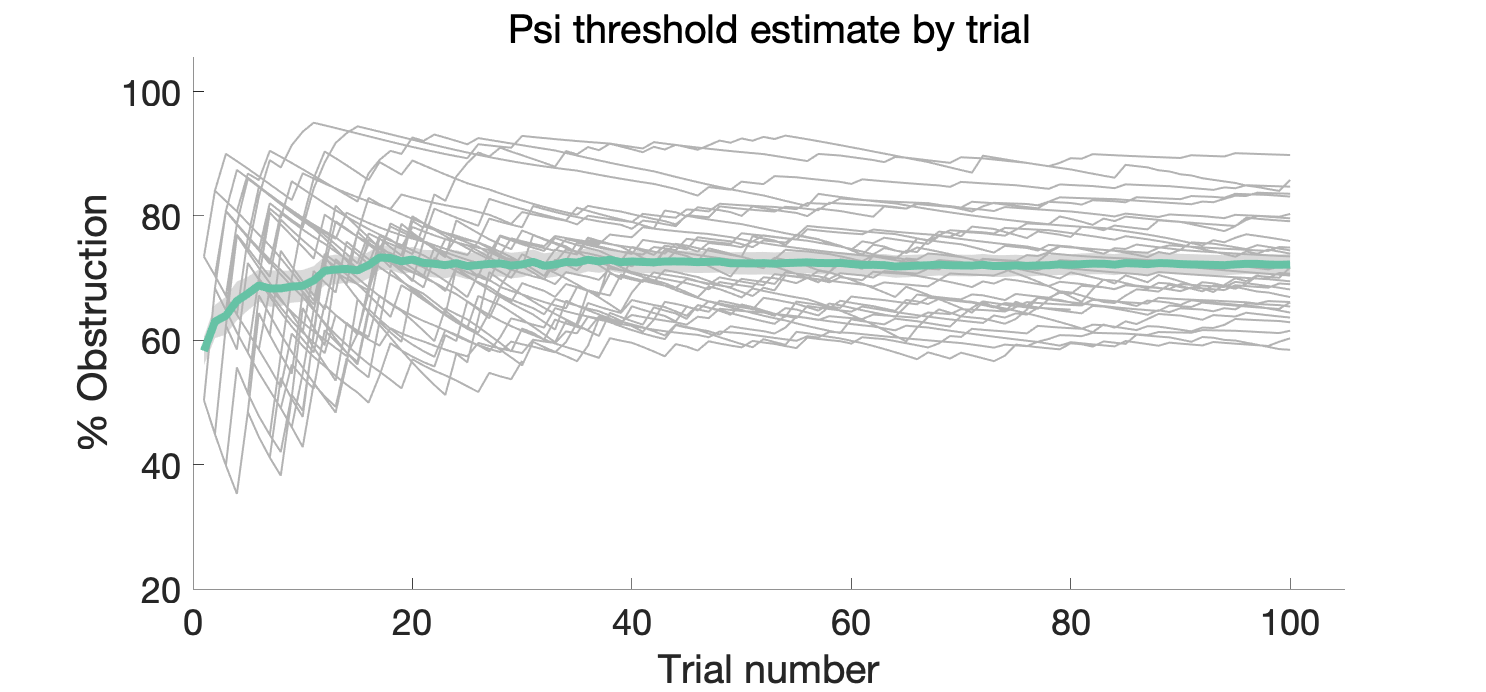

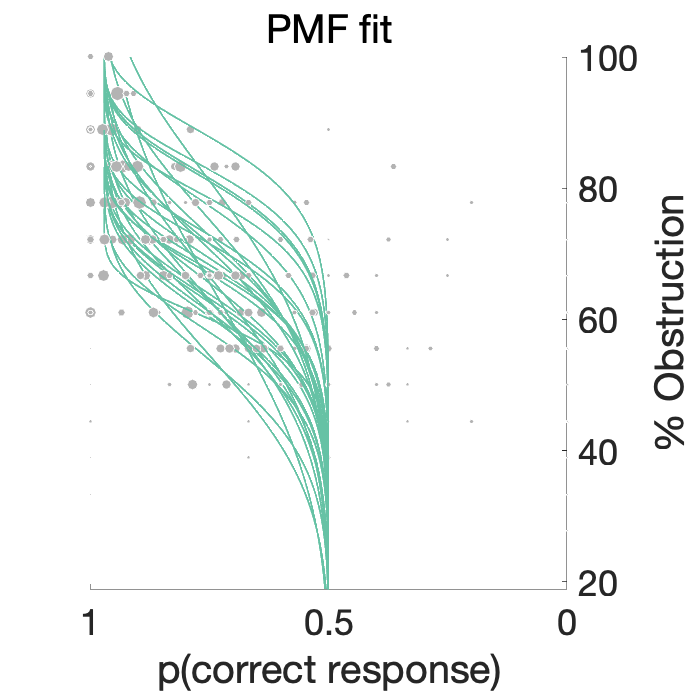

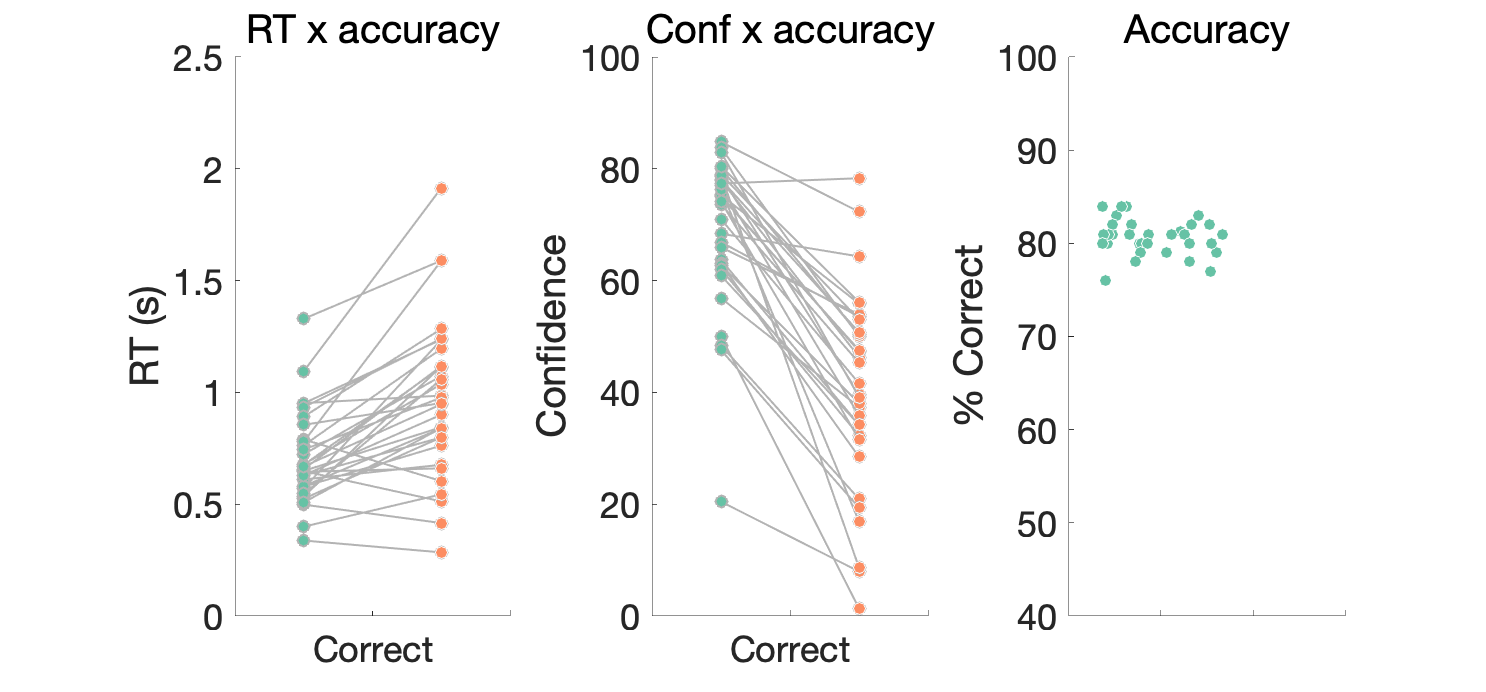

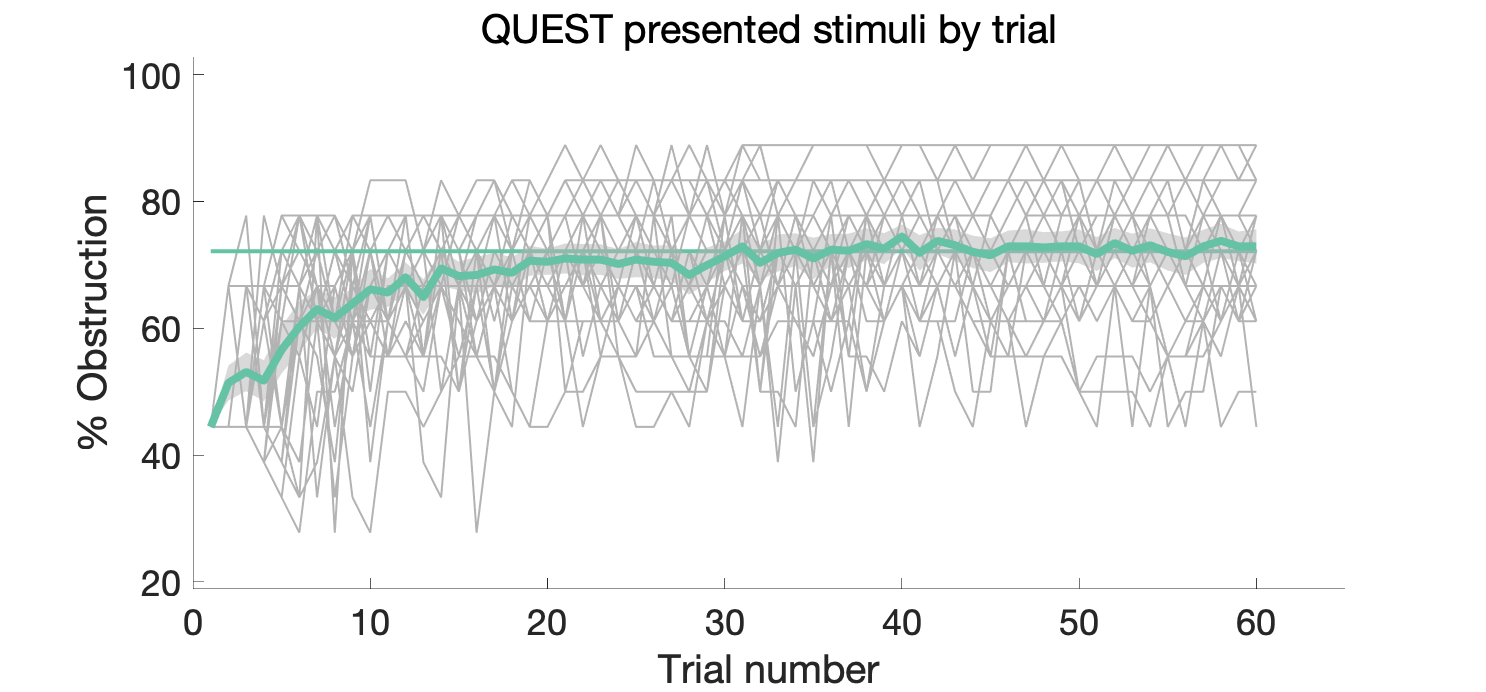

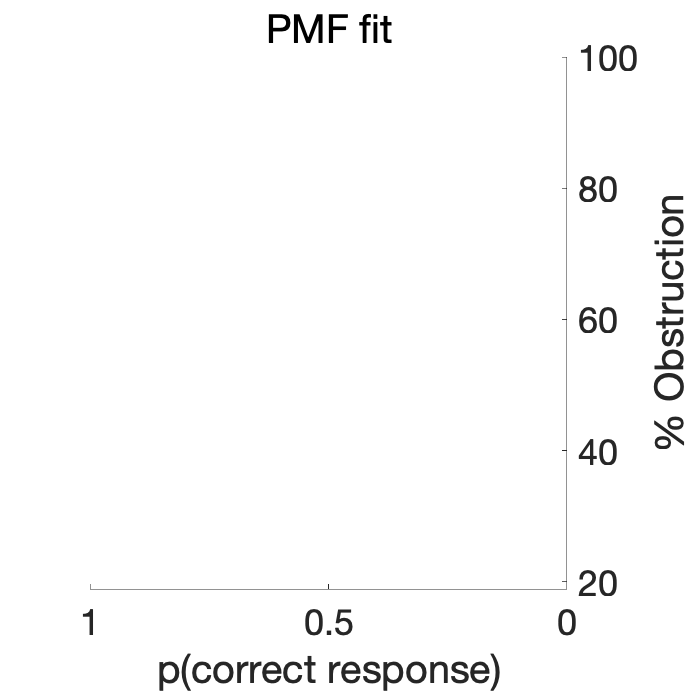

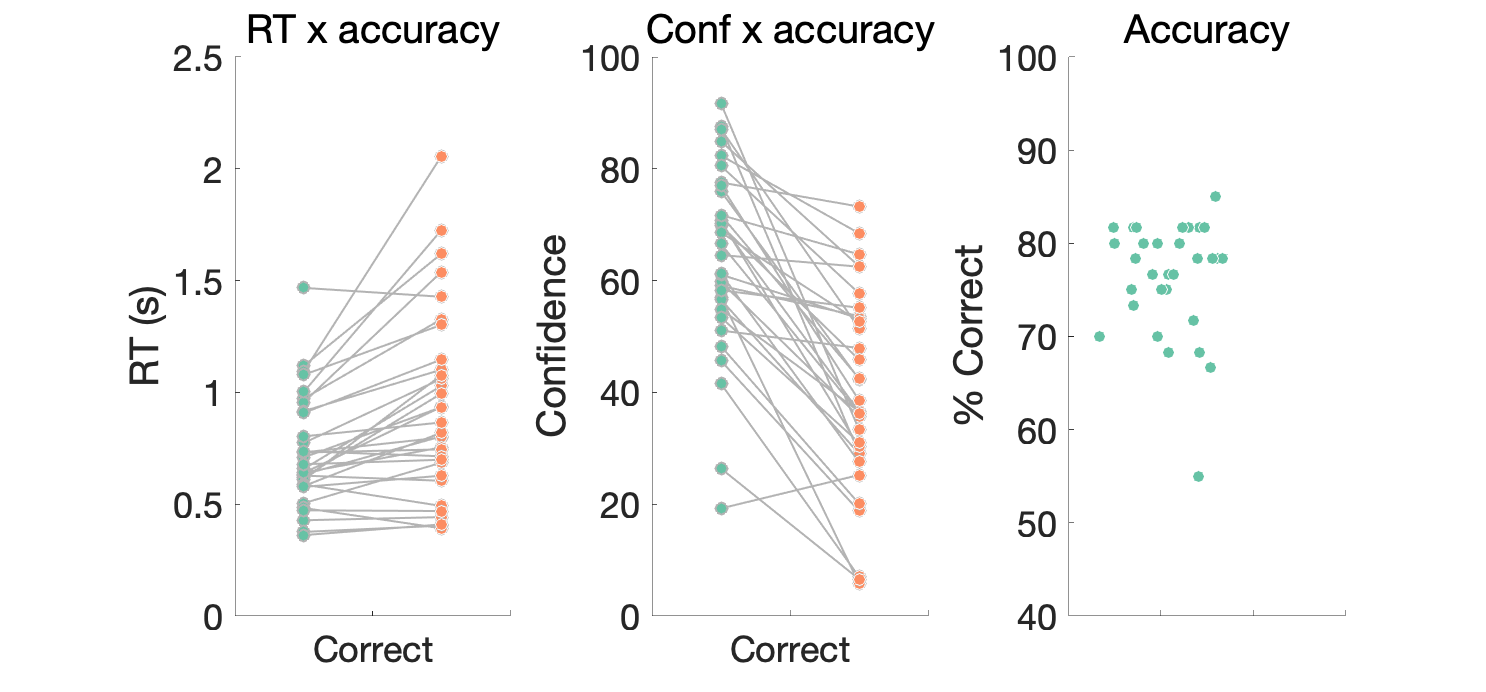

    %% E. Accuracy
    subplot(spRows,spCols,3); hold on;
    title('Accuracy','fontsize',fontSize+2,'FontWeight','Normal');
    set(gcf,'color','w');
    set(gca,'XTickLabels', {'','','',''});
    axis([0 3 40 100]);
    ylabel('% Correct','fontsize',fontSize);
    set(gca,'FontName',fontName,'fontsize',fontSize);
    hold on;
    
    % Loop over subjects & plot
    for thisSub = 1 : length(subNo)
        thisSubId = subNo(thisSub);
        
        responses       = data(data.ID==thisSubId, :).response;
        correctTrials   = sum(responses == 1);
        accuracy        = (correctTrials / length(responses(~isnan(responses)))).*100;
        
        scatter(1, accuracy, 'wo', 'jitter','on', 'jitterAmount', 0.7, 'markerfacecolor',cl(1,:));
        hold on
        
    end
end

## FIGURE 3

Set up yhe figure


% fig_position    = [200,200,830,400];
fig_position    = [200,200,415,400];
f1      = figure('Position', fig_position);
set(gcf,'color','w');
% sgt = sgtitle(['SEs by trial']);
% sgt.FontSize = fontsize+2;
spCols  = 2;
spRows  = 1;

A. trial x SE threshold

%% A. trial x SE threshold
% Create figure with 1x2 subplot
% subplot(spRows,spCols,1); hold on;

xVal    = psidata.trialN;
yVal    = psidata.SEthresh;
temp    = [xVal, yVal]';
nMaxTrials = max(xVal);

trialWiseSE     = nan(100,nMaxTrials);          % preallocate large nan array

% Align all values to trial numbers
for thisTrial = 1 : nMaxTrials
    % get indeces for columns with this trial #
    thisTrialCol        = temp(2,(temp(1,:)==thisTrial));
    % add to trialsWiseSE mat
    datLength           = size(thisTrialCol,2);
    trialWiseSE(1:datLength, thisTrial)   = thisTrialCol';
    
    clear thisTrialCol datLength
end
trialWiseSE(all(isnan(trialWiseSE), 2), :) = [];        % clear all-nan rows


Calculate mean & CI at each trial

% Calculate mean & CI at each trial
N       = size(trialWiseSE,1); 
seThresh_mean   = nanmean(trialWiseSE);   	% Mean each Value Of ?x?
stdThresh       = std(trialWiseSE,'omitnan');
ySEM    = stdThresh/sqrt(N);                % Compute ?Standard Error Of The Mean? Of All Experiments At Each Value Of ?x?
CI95    = tinv([0.025 0.975], N-1);       	% Calculate 95% Probability Intervals Of t-Distribution
yCI95   = bsxfun(@times, ySEM, CI95(:));   	% Calculate 95% Confidence Intervals Of All Experiments At Each Value Of ?x?

% Simple plot of SE mean and 95% CI
% figure
% plot(1:nMaxTrials, seThresh_mean)                                      % Plot Mean Of All Experiments
% hold on
% plot(1:nMaxTrials, yCI95+seThresh_mean)                                % Plot 95% Confidence Intervals Of All Experiments
% hold off
% grid


Plot CI as filled area using ciplot

% Plot CI as filled area using ciplot
lower   = yCI95(1,:)+seThresh_mean;
upper   = yCI95(2,:)+seThresh_mean;
ciplot(lower,upper,[1:nMaxTrials],cl(3,:));         % Plot 95% CI as filled area
hold on
plot(1:nMaxTrials, seThresh_mean,'Color',cl(1,:),'LineWidth',lineWidth+1);    % Add mean line


% % Plot raw SE data
% plot(data.trialN,data.SEthresh,'Color',cl(3,:),'LineWidth',lineWidth);

Format the figure

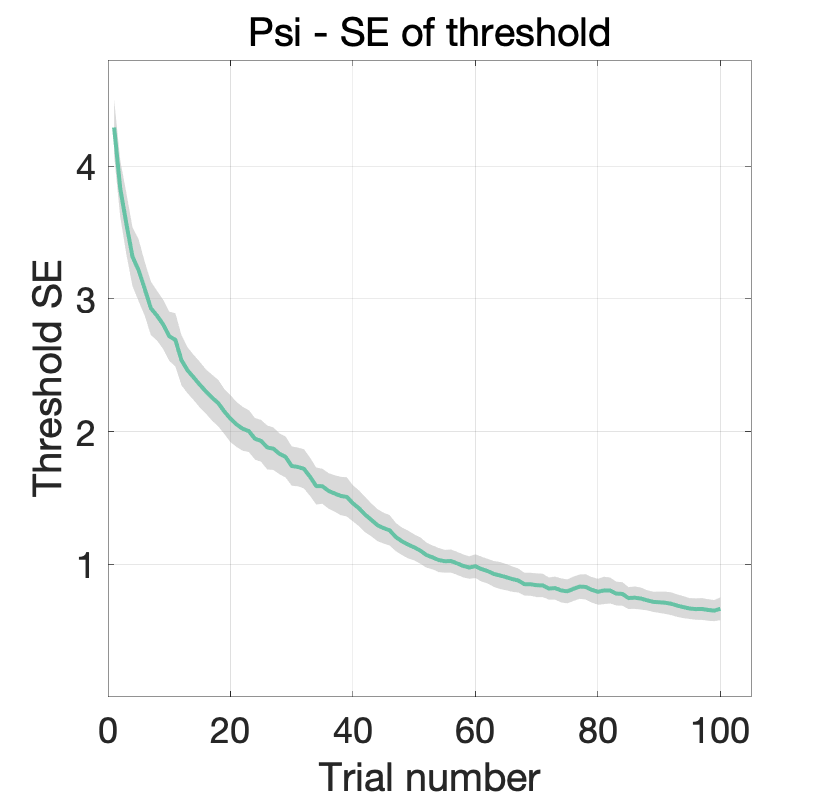

% Format
title('Psi - SE of threshold','fontsize',fontSize+2,'FontWeight','Normal');
axis([0 105 0 4.8]);
grid on
yticks([0, 1, 2, 3, 4]);
yticklabels({'', '1', '2', '3', '4'});
xlabel('Trial number','fontsize',fontSize);
ylabel('Threshold SE','fontsize',fontSize);
set(gca,'FontName',fontName,'fontsize',fontSize)
hold on

B. trial x SE slope

fig_position    = [200,200,415,400];
f1      = figure('Position', fig_position);
set(gcf,'color','w');

xVal    = psidata.trialN;
yVal    = psidata.SEslope;
temp    = [xVal, yVal]';
nMaxTrials = max(xVal);

trialWiseSE     = nan(100,nMaxTrials);          % preallocate large nan array

% Align all values to trial numbers
for thisTrial = 1 : nMaxTrials
    % get indeces for columns with this trial #
    thisTrialCol        = temp(2,(temp(1,:)==thisTrial));
    % add to trialsWiseSE mat
    datLength           = size(thisTrialCol,2);
    trialWiseSE(1:datLength, thisTrial)   = thisTrialCol';
    
    clear thisTrialCol datLength
end
trialWiseSE(all(isnan(trialWiseSE), 2), :) = [];        % clear all-nan rows

% Calculate mean & CI at each trial
N       = size(trialWiseSE,1); 
seSlope_mean   = nanmean(trialWiseSE);   	% Mean each Value Of ?x?
stdSlope       = std(trialWiseSE,'omitnan');
ySEM    = stdSlope/sqrt(N);                % Compute ?Standard Error Of The Mean? Of All Experiments At Each Value Of ?x?
CI95    = tinv([0.025 0.975], N-1);       	% Calculate 95% Probability Intervals Of t-Distribution
yCI95   = bsxfun(@times, ySEM, CI95(:));   	% Calculate 95% Confidence Intervals Of All Experiments At Each Value Of ?x?


% Plot CI as filled area using ciplot
lower   = yCI95(1,:)+seSlope_mean;
upper   = yCI95(2,:)+seSlope_mean;
ciplot(lower,upper,[1:nMaxTrials],cl(3,:));         % Plot 95% CI as filled area
hold on
plot(1:nMaxTrials, seSlope_mean,'Color',cl(1,:),'LineWidth',lineWidth+1);    % Add mean line


% % Plot raw slope SE data
% plot(data.trialN,data.SEslope,'Color',cl(3,:),'LineWidth',lineWidth);


% Format
title('Psi - SE of slope','fontsize',fontSize+2,'FontWeight','Normal');
axis([0 105 0 .48]);
grid on
xlabel('Trial number','fontsize',fontSize);
ylabel('Slope SE','fontsize',fontSize);
yticks([0, 0.1, 0.2, 0.3, 0.4]);
yticklabels({'', '0.1', '0.2', '0.3', '0.4'});
set(gca,'FontName',fontName,'fontsize',fontSize)
hold off

C. Error to threshold, QUEST  % Uncomment when analysing QUEST

% fig_position    = [200,200,415,400];
% f5              = figure('Position', fig_position);
% set(gcf,'color','w');
% hold on;
% 
% % -------------------------------------------------------------------------
% % A. QUEST
% trialStims  = questdata.stimLevel;
% threshEst   = questdata.thresh;
% % Calculate difference to threshold estimate for each trial
% estDifference   = abs(trialStims - threshEst);
% questdata.Diffthresh = estDifference;
% 
% xVal    = questdata.trialN;
% yVal    = questdata.Diffthresh;
% temp    = [xVal, yVal]';
% nMaxTrials = max(xVal);
% 
% trialWiseSE     = nan(100,nMaxTrials);          % preallocate large nan array
% 
% % Align all values to trial numbers
% for thisTrial = 1 : nMaxTrials
%     % get indeces for columns with this trial #
%     thisTrialCol        = temp(2,(temp(1,:)==thisTrial));
%     % add to trialsWiseSE mat
%     datLength           = size(thisTrialCol,2);
%     trialWiseSE(1:datLength, thisTrial)   = thisTrialCol';
%     
%     clear thisTrialCol datLength
% end
% trialWiseSE(all(isnan(trialWiseSE), 2), :) = [];        % clear all-nan rows
% 
% % Calculate mean & CI at each trial
% N       = size(trialWiseSE,1); 
% seThresh_mean   = nanmean(trialWiseSE);   	% Mean each Value Of ?x?
% stdThresh       = std(trialWiseSE,'omitnan');
% ySEM    = stdThresh/sqrt(N);                % Compute ?Standard Error Of The Mean? Of All Experiments At Each Value Of ?x?
% CI95    = tinv([0.025 0.975], N-1);       	% Calculate 95% Probability Intervals Of t-Distribution
% yCI95   = bsxfun(@times, ySEM, CI95(:));   	% Calculate 95% Confidence Intervals Of All Experiments At Each Value Of ?x?
% 
% % Plot CI as filled area using ciplot
% lower   = yCI95(1,:)+seThresh_mean;
% upper   = yCI95(2,:)+seThresh_mean;
% ciplot(lower,upper,[1:nMaxTrials],cl(3,:));         % Plot 95% CI as filled area
% hold on
% h1=plot(1:nMaxTrials, seThresh_mean,'Color',cl(1,:),'LineWidth',lineWidth+1);    % Add mean line


B. PSI

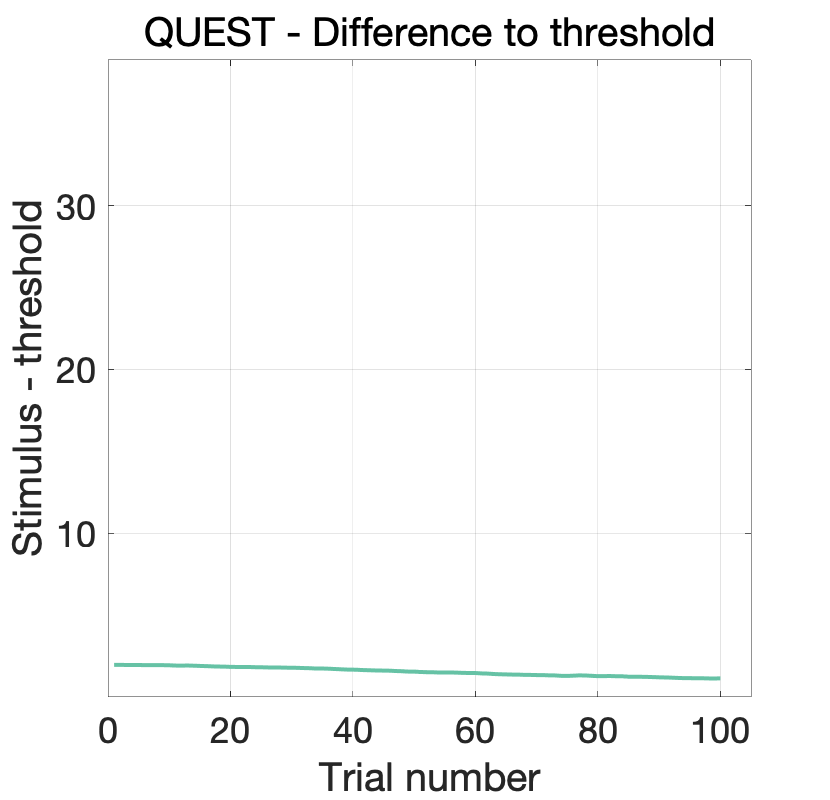

trialStims  = psidata.stimLevel;
threshEst   = psidata.thresh;
% Calculate difference to threshold estimate for each trial
estDifference   = abs(trialStims - threshEst);
psidata.Diffthresh = estDifference;

xVal    = psidata.trialN;
yVal    = psidata.Diffthresh;
temp    = [xVal, yVal]';
nMaxTrials = max(xVal);

trialWiseSE     = nan(100,nMaxTrials);          % preallocate large nan array

% Align all values to trial numbers
for thisTrial = 1 : nMaxTrials
    % get indeces for columns with this trial #
    thisTrialCol        = temp(2,(temp(1,:)==thisTrial));
    % add to trialsWiseSE mat
    datLength           = size(thisTrialCol,2);
    trialWiseSE(1:datLength, thisTrial)   = thisTrialCol';
    
    clear thisTrialCol datLength
end
trialWiseSE(all(isnan(trialWiseSE), 2), :) = [];        % clear all-nan rows

% Calculate mean & CI at each trial
N       = size(trialWiseSE,1); 
seThresh_mean   = nanmean(trialWiseSE);   	% Mean each Value Of ?x?
stdThresh       = std(trialWiseSE,'omitnan');
ySEM    = stdThresh/sqrt(N);                % Compute Standard Error Of The Mean Of All Experiments At Each Value Of x
CI95    = tinv([0.025 0.975], N-1);       	% Calculate 95% Probability Intervals Of t-Distribution
yCI95   = bsxfun(@times, ySEM, CI95(:));   	% Calculate 95% Confidence Intervals Of All Experiments At Each Value Of x

% Plot CI as filled area using ciplot
lower   = yCI95(1,:)+seThresh_mean;
upper   = yCI95(2,:)+seThresh_mean;
% ciplot(lower,upper,[1:nMaxTrials],cl(3,:));         % Plot 95% CI as filled area
% hold on
% h2=plot(1:nMaxTrials, seThresh_mean,'Color',cl(2,:),'LineWidth',lineWidth+1);    % Add mean line


% Format
title('QUEST - Difference to threshold','fontsize',fontSize+2,'FontWeight','Normal');
% axis([0 65 0 7]);
axis([0 105 0 7]);
grid on
yticks([1.8, 3.6, 5.4]);
yticklabels({'10', '20','30'});
xlabel('Trial number','fontsize',fontSize);
ylabel('Stimulus - threshold','fontsize',fontSize);
set(gca,'FontName',fontName,'fontsize',fontSize)
hold on


% % Add legend
% legend([h1 h2],{'QUEST', 'Psi'},'fontsize',fontSize);
% legend boxoff 

## Figure, rainclouds for RT x accuracy , stim level x accuracy

Set up the figure

fig_position    = [200,200,830,800];
f2  = figure('Position', fig_position);
set(gcf,'color','w');
   

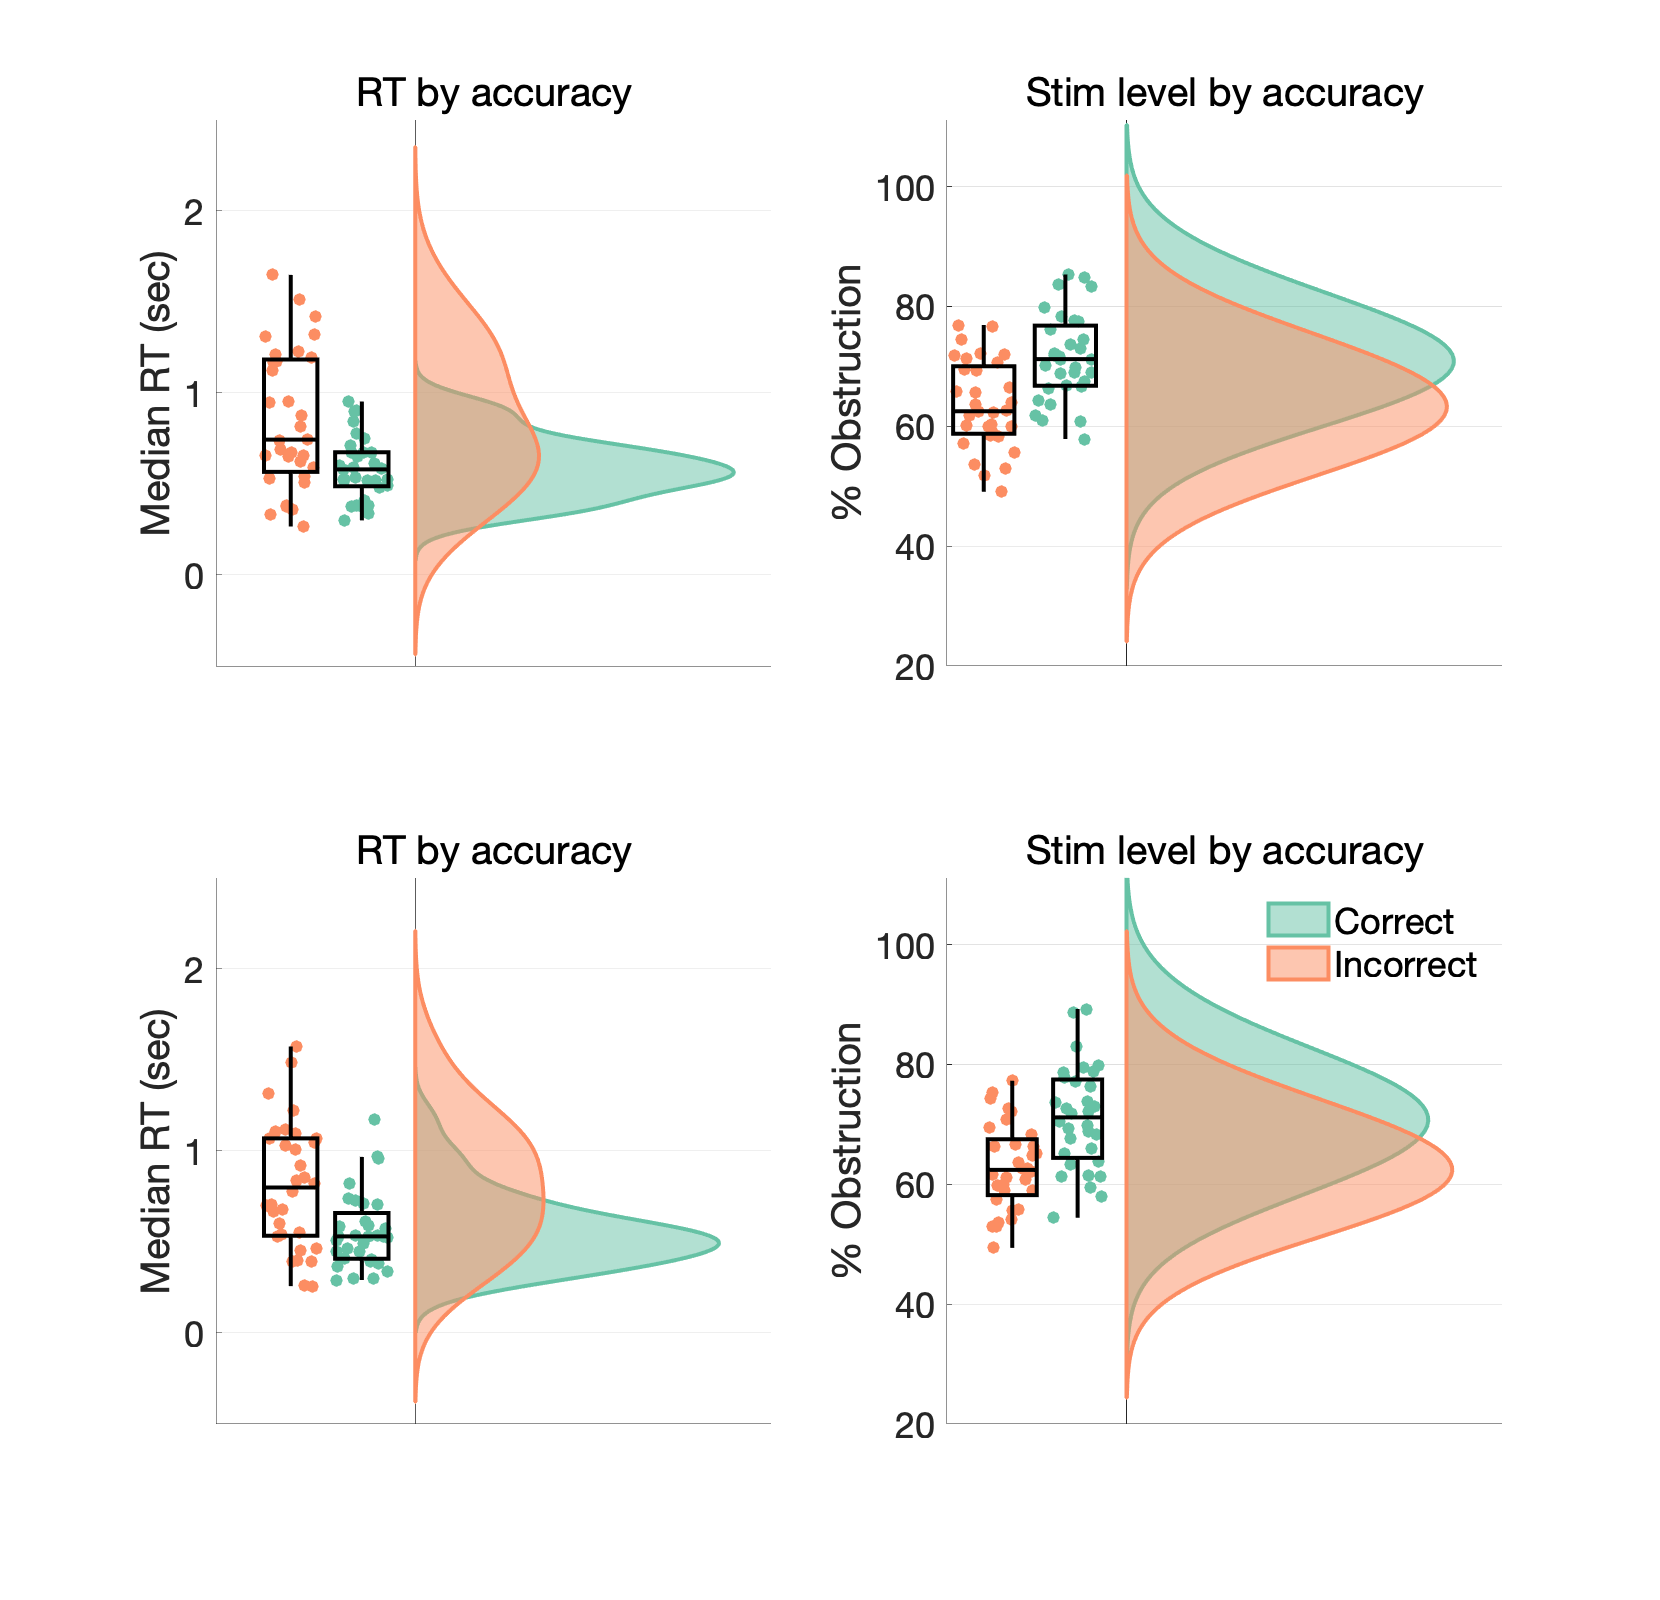

Effect of accuracy on RTs, t-test results: 


h = 1

p = 8.8635e-04

ci =    -0.4101
   -0.1141


stats = struct with fields:
    tstat: -3.5722
       df: 43.1007
       sd: [2×1 double]


Psi


Effect of accuracy on Stim levels, t-test results: 


h = 1

p = 4.9488e-05

ci =     0.7738
    2.0827


stats = struct with fields:
    tstat: 4.3626
       df: 62
       sd: 1.3095


Effect of accuracy on RTs, t-test results: 


h = 1

p = 9.1404e-04

ci =    -0.3941
   -0.1080


stats = struct with fields:
    tstat: -3.5232
       df: 50.6053
       sd: [2×1 double]


Quest


Effect of accuracy on Stim levels, t-test results: 


h = 1

p = 1.0761e-04

ci =     0.7576
    2.1739


stats = struct with fields:
    tstat: 4.1376
       df: 62
       sd: 1.4170


for psiOrQuest = 1:2
    
    % RT
    % Calculate median corr & incorr RT for each subject
    allSubjectsRTs  = [];
    if psiOrQuest == 2  % Quest
        subNbs          = unique(questdata.ID);
        nSubjects       = size(subNbs,1);
        corrMat         = questcorr;
        incorrMat       = questincorr;
    else                % Psi
        subNbs          = unique(psidata.ID);
        nSubjects       = size(subNbs,1);
        corrMat         = psicorr;
        incorrMat       = psiincorr;
    end
    
    for thisSubIdx = 1 : nSubjects
        thisSub     = subNbs(thisSubIdx);
        idxC        = corrMat.ID == thisSub;
        idxI        = incorrMat.ID == thisSub;
        RTs{1}        = table2array(corr(idxC,8)); % RT on correct trials
        RTs{2}        = table2array(incorr(idxI,8)); % RT on incorrect trials
        
        medians     = cellfun(@median, RTs);
        allSubjectsRTs  = [allSubjectsRTs; medians];
    end
    
    if psiOrQuest == 1
        spN = 1;
    elseif psiOrQuest == 2
        spN = 3;
    end
    subplot(2, 2, spN) 
    % subplot(1, 2, 1)
    h1 = raincloud_plot(allSubjectsRTs(:,1), 'box_on', 1, 'color', cl(1,:), 'alpha', 0.5, 'cloud_edge_col', cl(1,:),...
        'box_dodge', 1, 'box_dodge_amount', .15, 'dot_dodge_amount', .15,...
        'box_col_match', 0);
    h2 = raincloud_plot(allSubjectsRTs(:,2), 'box_on', 1, 'color', cl(2,:), 'alpha', 0.5, 'cloud_edge_col', cl(2,:),...
        'box_dodge', 1, 'box_dodge_amount', .35, 'dot_dodge_amount', .35, 'box_col_match', 0);
    set(h1{2}, 'SizeData', scatterMarkerSize);
    set(h2{2}, 'SizeData', scatterMarkerSize);
    title(['RT by accuracy'],'fontsize',fontSize+2,'FontWeight','Normal');
    xlabel('Median RT (sec)');
    xticks([0,1,2,3]);
    yticks([]);
    ax = gca;
    ax.XGrid = 'on';
    ax.YGrid = 'off';
    box off; hold on;
    set(gca,'XLim', [-.5 2.5], 'YLim', [-1.4 2.5],'FontName',fontName,'fontsize',fontSize);
    set(gca,'XAxisLocation','bottom','YAxisLocation','right','xdir','reverse');
    
    % % Uncomment if we want to display a superlabel on the y axis, e.g. QUEST
    % [~,h1] = suplabel('QUEST','y');
    % set(h1,'FontName',fontName,'fontsize',fontSize+5);
    
    camroll(-90)
    
    % Stats, T-test
    disp(['Effect of accuracy on RTs, t-test results: ']);
    [h,p,ci,stats] = ttest2(allSubjectsRTs(:,1),allSubjectsRTs(:,2),'vartype','unequal')
    
    
    clear d means idxC idxI
    
    % Stim level x accuracy
    % Get the data to plot into two columns, get mean and var
    allSubjectsSLs  = [];
    for thisSubIdx = 1 : nSubjects
        thisSub     = subNbs(thisSubIdx);
        idxC        = corrMat.ID == thisSub;
        idxI        = incorrMat.ID == thisSub;
        d{1}        = table2array(corr(idxC,3));      % SL on correct trials
        d{2}        = table2array(incorr(idxI,3));    % SL on incorrect trials
        
        means     = cellfun(@mean, d);
        allSubjectsSLs  = [allSubjectsSLs; means];
    end
    
    if psiOrQuest == 1      % Psi
        spN = 2;
        textStr     = 'Psi';
    elseif psiOrQuest == 2  % Quest
        spN = 4;
        textStr     = 'Quest';
    end
    subplot(2, 2, spN) 
    % subplot(1, 2, 2)
    h1 = raincloud_plot(allSubjectsSLs(:,1), 'box_on', 1, 'color', cl(1,:), 'alpha', 0.5, 'cloud_edge_col', cl(1,:),...
        'box_dodge', 1, 'box_dodge_amount', .15, 'dot_dodge_amount', .15,...
        'box_col_match', 0, 'band_width', 1.5);
    h2 = raincloud_plot(allSubjectsSLs(:,2), 'box_on', 1, 'color', cl(2,:), 'alpha', 0.5, 'cloud_edge_col', cl(2,:),...
        'box_dodge', 1, 'box_dodge_amount', .35, 'dot_dodge_amount', .35, 'box_col_match', 0, ...
        'band_width', 1.5);
    set(h1{2}, 'SizeData', scatterMarkerSize);
    set(h2{2}, 'SizeData', scatterMarkerSize);
    if spN == 4
        legend([h1{1} h2{1}], {'Correct', 'Incorrect'},'fontsize',fontSize);
        legend boxoff
    end
    title(['Stim level by accuracy'],'fontsize',fontSize+2,'FontWeight','Normal');
    xlabel('% Obstruction');
    xticks([3.6, 7.2, 10.8, 14.4, 18]);
    xticklabels({'20', '40', '60', '80', '100'});
    yticks([]);
    ax = gca;
    ax.XGrid = 'on';
    ax.YGrid = 'off';
    box off; hold on;
    set(gca,'XLim', [3.6 20], 'YLim', [-.11 .23],'FontName',fontName,'fontsize',fontSize);
    set(gca,'XAxisLocation','bottom','YAxisLocation','right','xdir','reverse');
    
    camroll(-90)
    
    % Stats, T-test
    disp(newline)
    disp(textStr)
    disp('Effect of accuracy on Stim levels, t-test results: ');
    [h,p,ci,stats] = ttest2(allSubjectsSLs(:,1),allSubjectsSLs(:,2))
    
    clear d means idxC idxI 
end

### Figure XX, grand mean PMF

% Create figure & format
fig_position    = [200,200,346,346];
f3  = figure('Position', fig_position);
title(['Group psychometric function fit'],'fontsize',fontSize+2,'FontWeight','Normal');
set(gcf,'color','w');
axis([3.4 18 .5 1]);
% xticks([3.4, 6.8, 10.2, 13.6, 17]);
% xticklabels({'20', '40', '60', '80', '100'});
xticks([3.6, 7.2, 10.8, 14.4, 18]);
xticklabels({'20', '40', '60', '80', '100'});
xlabel('% Obstruction');
ylabel('p(correct)');
set(gca,'fontsize',fontSize,'FontName',fontName)
grid on
hold on

% Loop over subjects & plot
subNo  	= table2array(unique(psidata(:,1)));
data    = table2array(psidata);
allThresholds   = [];
allSlopes       = [];
for thisSub = 1 : length(subNo)
    thisSubId = subNo(thisSub,1);
    
    % Calculate Threshold and Slope 
    threshEst   = data(data(:,1)==thisSubId, 10);
    threshEst   = threshEst(end);
    slopeEst    = data(data(:,1)==thisSubId, 11);
    slopeEst    = 10.^slopeEst(end);
    
    PF          = @PAL_Weibull;
    gamma       = 0.5;
    lambda      = 0.03;
    
    stimuli     = data(data(:,1)==thisSubId, 3);
    
    % Plot
    plot([0:.01:max(stimuli)+1], PF([threshEst slopeEst gamma lambda],0:.01:max(stimuli)+1),'Color',cl(3,:),'linewidth',lineWidth/2,'HandleVisibility','off')
   
    thisSubThresh   = (threshEst*100/18);                                   % scale from mm to % obstruction
    allThresholds   = [allThresholds; thisSubThresh];
    thisSubSlope   	= slopeEst;                                   % scale from mm to % obstruction
    allSlopes       = [allSlopes; thisSubSlope];
end

disp(['Max threshold: ', num2str(max(allThresholds))]);

Max threshold: 89.793


disp(['Min threshold: ', num2str(min(allThresholds))]);

Min threshold: 56.7099


disp(['STD threshold: ', num2str(nanstd(allThresholds))]);

STD threshold: 8.4724



disp(['Max slope: ', num2str(max(allSlopes))]);

Max slope: 12.3673


disp(['Min slope: ', num2str(min(allSlopes))]);

Min slope: 3.1153


disp(['Mean slope: ', num2str(nanmean(allSlopes))]);

Mean slope: 7.7972


disp(['STD slope: ', num2str(nanstd(allSlopes))]);

STD slope: 2.6076


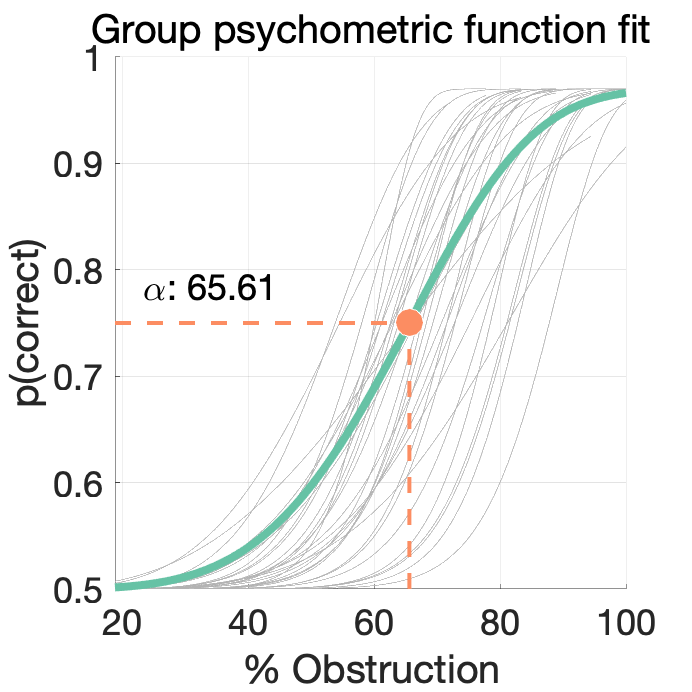



% Mean pmf
PF          = @PAL_Weibull;
gamma       = 0.5;
lambda      = 0.03;
grain       = 50;

sgrid.alpha  = linspace(PF([6 2 0 0],.1,'inverse'),PF([6 2 0 0],.9999,'inverse'),grain);
sgrid.beta   = linspace(log10(1),log10(16),grain);
sgrid.gamma  = gamma;
sgrid.lambda = lambda;

stimuli     = data(:, 3);
responses   = data(:, 5);
nPresented  = ones(size(stimuli));

maxStim     = max(stimuli);

% bayesian fit of PMF
[SL, NP, OON] = PAL_PFML_GroupTrialsbyX(stimuli',responses',nPresented');
[paramsValues, ~] = PAL_PFBA_Fit(SL, NP, ...
    OON, sgrid, PF);

threshEst   = paramsValues(1,1);
slopeEst    = 10.^(paramsValues(1,2));

% Add reference line for threshold level of 75% correct
y1 = PF([threshEst slopeEst gamma lambda],0:.01:max(stimuli)+1);        % Psychometric function fit
y2 = 0.75 * ones(size(y1));                                             % Threshold level                
x1 = [0:.01:max(stimuli)+1];                                            
[xInt,yInt] = intersections(x1,y1,x1,y2);

% Add a vertical line to indicate the threshold
plot([0 xInt],[yInt yInt],'--','Color',cl(2,:),'linewidth',lineWidth*2)
plot([xInt xInt],[0 .75],'--','Color',cl(2,:),'linewidth',lineWidth*2)

% Plot PMF
plot([0:.01:max(stimuli)+1], PF([threshEst slopeEst gamma lambda],0:.01:max(stimuli)+1),'Color',cl(1,:),'linewidth',lineWidth*4)

% Add marker at threshold and text, '[Threshold:  num2str(round(xInt))]'
plot(xInt,.75,'wo','markerfacecolor',cl(2,:),'markersize', 14)
xIntScal        = (xInt*100/maxStim);                                   % scale from mm to % obstruction
threshLabel     = ['\alpha: ', num2str(round(xIntScal,2))];
text(4.2,.785,threshLabel,'FontSize',fontSize,'FontName',fontName)

## Metacognition analysis

Set up

saveMetacogResults  = 0;
nRatings            = 4;
metacogDir          = fullfile('..','data','metacog');

% Loop over subjects & bin confidence ratings
subNo           = table2array(unique(psidata(:,1)));
mdata           = table2array(psidata);
mdata(:,end+1)  = nan((size(mdata,1)),1);
alldiscRatings  = [];

Bin ratings

% THIS DROPS TWO SUBJECTS (30 & 32) due to bad ratings, they entered almost
% exclusively 0 or 100

for thisSub = 1 : length(subNo)
    thisSubId = subNo(thisSub,1);

    rawRatings = mdata(mdata(:,1)==thisSubId, 7);

    try
        discRatings     = new_bin_ratings(rawRatings, nRatings);
    catch
        discRatings     = nan(size(rawRatings, 1),1)';
        disp(['Dropping subject due to bad binning: subject ', num2str(thisSubId)])
    end
   
    alldiscRatings = [alldiscRatings, discRatings];
    
    clear rr_temp
end

Lots of low confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings
Lots of high confidence ratings


Dropping subject due to bad binning: subject 30


Lots of high confidence ratings


Dropping subject due to bad binning: subject 32



% Add discrete ratings to last column of mdata array
mdata(:,end)    = alldiscRatings';

## Loop over subjects, & convert trials to counts

metaCountsAll   = nan(2,nRatings*2,length(subNo));  % nR_S1, nR_S2; nSubjects
aROCAll         = [];
for thisSub = 1 : length(subNo)
    thisSubId = subNo(thisSub,1);
    
    stimIDtemp  = mdata(mdata(:,1)==thisSubId, 4);  % Then convert this to 0=S1 or 1=S2
    stimIDtemp(stimIDtemp(:)==1)=0;
    stimIDtemp(stimIDtemp(:)==2)=1;
    stimID      = stimIDtemp;                       % 0 S1, 1 S2
    sResponse   = mdata(mdata(:,1)==thisSubId, 6);  % 0 S1, 1 S2
    rating      = mdata(mdata(:,1)==thisSubId, 16);

    % Convert to counts for each rating
    [nR_S1, nR_S2] = trials2counts(stimID,sResponse,rating,nRatings);
    metaCountsAll(:,:,thisSub) = [nR_S1; nR_S2];
    
    % For each subject, calculate the area under the Type 2 ROC
    auroc2 = cpc_type2roc(nR_S1, nR_S2, nRatings);
    aROCAll     = [aROCAll; auroc2];        % array with all subjects aROC2
    
end
% Note that metaCountsAll and files for subjects 30 & 32 (bad ratings) are
% all zeros

addpath(metacogDir)

files           = dir(metacogDir);
filenames       = GetFields(files(4:end), 'name');      % first 2 are '.', '..'

% Summary statistics on aROC2
aROC_max    = max(aROCAll);
aROC_min    = min(aROCAll);
aROC_mean   = nanmean(aROCAll);
AROC_std    = nanstd(aROCAll);



## Fit meta d' 

This step will take about 2-3 minutes for 33 subjects

Already saved in /data/metacog so don't need to do this again

Figure: confidence ratings histogram

% Collapse across two stimuli for correct and incorrect responses,get proportion of all correct/ incorrect ratings
obsCount = (metaCountsAll(1,:,:) + fliplr(metaCountsAll(2,:,:)));           % this gives flipped corrects followed by incorrects (ratings c4 c3 c2 c1 i1 i2 i3 i4)
C_all_prop_data = [];
I_all_prop_data = [];
for thisSub = 1:size(obsCount,3)
    sData       = obsCount(:,:,thisSub);                                % get the subjects data
    C_prop_data = fliplr(sData(1:nRatings))./sum(sData(1:nRatings));    % flip correct ratings back (low->high)
    I_prop_data = sData(nRatings+1:2*nRatings)./sum(sData(nRatings+1:2*nRatings));
    
    C_all_prop_data = [C_all_prop_data; C_prop_data];
    I_all_prop_data = [I_all_prop_data; I_prop_data];
end

    
% Inter-subject mean
C_prop_mean     = nanmean(C_all_prop_data,1);
I_prop_mean     = nanmean(I_all_prop_data,1);

% Calculate std error of mean
C_SEM = nanstd(C_all_prop_data,1)/sqrt(size(C_all_prop_data,1)); 
I_SEM = nanstd(I_all_prop_data,1)/sqrt(size(I_all_prop_data,1));                



## Figure, Confidence ratings histogram by accuracy

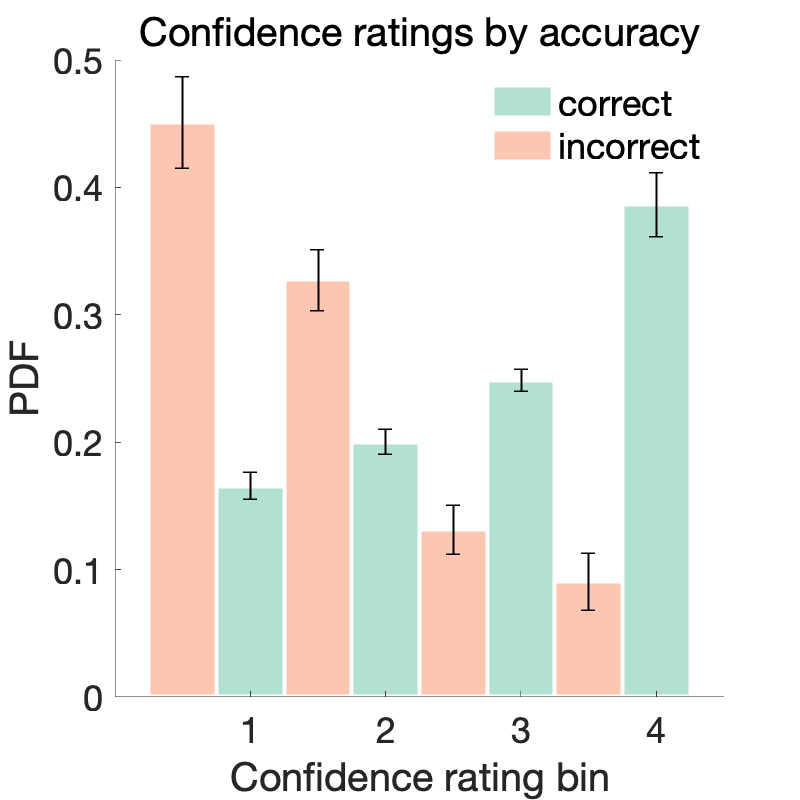

% fig_position    = [200,200,830,400];      % wide
fig_position    = [200,200,400,400];        % square
f4  = figure('Position', fig_position);
title(['Confidence ratings by accuracy'],'fontsize',fontSize+2,'FontWeight','Normal');
set(gcf,'color','w');
hold on

% Plot histogram (as barplot, since its already in proportions)
bar([1:nRatings+.5], C_prop_mean,0.5,'EdgeColor',[1 1 1],'FaceColor',cl(1,:),'FaceAlpha',.5,'LineWidth',lineWidth+1);
er = errorbar([1:nRatings+.5], C_prop_mean,C_SEM,'HandleVisibility','off');    
er.Color = [0 0 0];                            
er.LineStyle = 'none';  
er.LineWidth = lineWidth;

bar([1:nRatings]-.5, I_prop_mean,0.5,'EdgeColor',[1 1 1],'FaceColor',cl(2,:),'FaceAlpha',.5,'LineWidth',lineWidth+1);
hold on
er = errorbar([1:nRatings]-.5, I_prop_mean,I_SEM,'HandleVisibility','off');    
er.Color = [0 0 0];                            
er.LineStyle = 'none';
er.LineWidth = lineWidth;

% Edit figure properties
axis([0 4.5 0 0.5]);
xticks([1, 2, 3, 4]);
xticklabels({'1', '2', '3', '4'});
xlabel('Confidence rating bin');
ylabel('PDF');

legend({'correct','incorrect'},'FontSize',fontSize, 'FontName',fontName, 'Location', 'northeast');
legend boxoff
set(gca,'fontsize',fontSize,'FontName',fontName) 
set(gca,'Layer','top')

Stimulus level by confidence rating raincloud

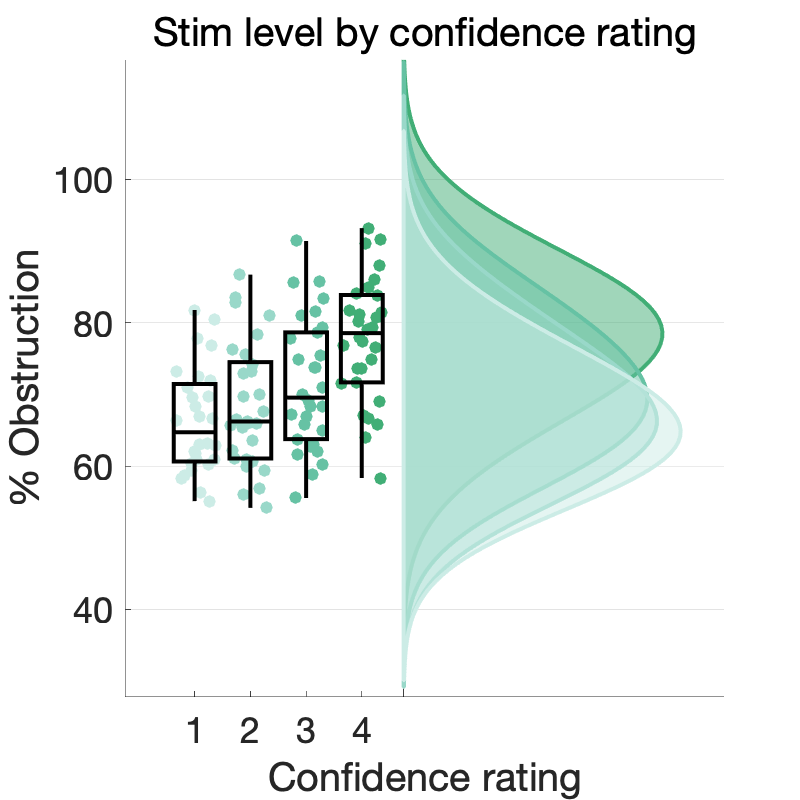


fig_position    = [200,200,400,400];%[200,200,346,346];
f7  = figure('Position', fig_position);
title(['Stimulus by confidence'],'fontsize',fontSize+2,'FontWeight','Normal');
set(gcf,'color','w');
allSubjectsSLs  = [];
for thisSub = 1 : nSubjects
    thisSubId       = subNo(thisSub,1);
    tempSLratings   = nan(1,4);
    subData         = mdata(mdata(:,1)==thisSubId,:);
    
    for thisRating = 1:nRatings
        meanSL  = nanmean(subData(subData(:,end)==thisRating,3));     % Get mean stimulus level for this rating
        tempSLratings(thisRating) = meanSL;
    end
    
    allSubjectsSLs = vertcat(allSubjectsSLs, tempSLratings);  
end

clear d
for thisRating = 1:nRatings
    d{thisRating}        = allSubjectsSLs(:,thisRating);      % SL for this rating
end


bd_val  = .15;
j       = 4;
clear yVal
for i = 1 : nRatings 
    yVal = d{j};
    h3 = raincloud_plot(yVal, 'box_on', 1, 'color', sq(j+2,:), 'alpha', 0.5, 'cloud_edge_col', sq(j+2,:),...
        'box_dodge', 1, 'box_dodge_amount', bd_val, 'dot_dodge_amount', bd_val,...
        'box_col_match', 0, 'band_width', 1.5);
    set(h3{2}, 'SizeData', scatterMarkerSize);
    
    bd_val  = bd_val+.2;
    j       = j-1;
end
   
title(['Stim level by confidence rating'],'fontsize',fontSize+2,'FontWeight','Normal');
xlabel('% Obstruction');
ylabel('Confidence rating');
axis([5 21 -.2 .23]);
xticks([3.6, 7.2, 10.8, 14.4, 18]);
xticklabels({'20', '40', '60', '80', '100'});
yticks([-.15, -.11, -.07, -.03]);
yticklabels({'1', '2', '3', '4'});
ax = gca;
set(ax,'fontsize',fontSize,'FontName',fontName) 
ax.XGrid = 'on';
ax.YGrid = 'off';
box off; hold on;
set(gca,'XAxisLocation','bottom','YAxisLocation','right','xdir','reverse');

camroll(-90)

Type 2 ROC

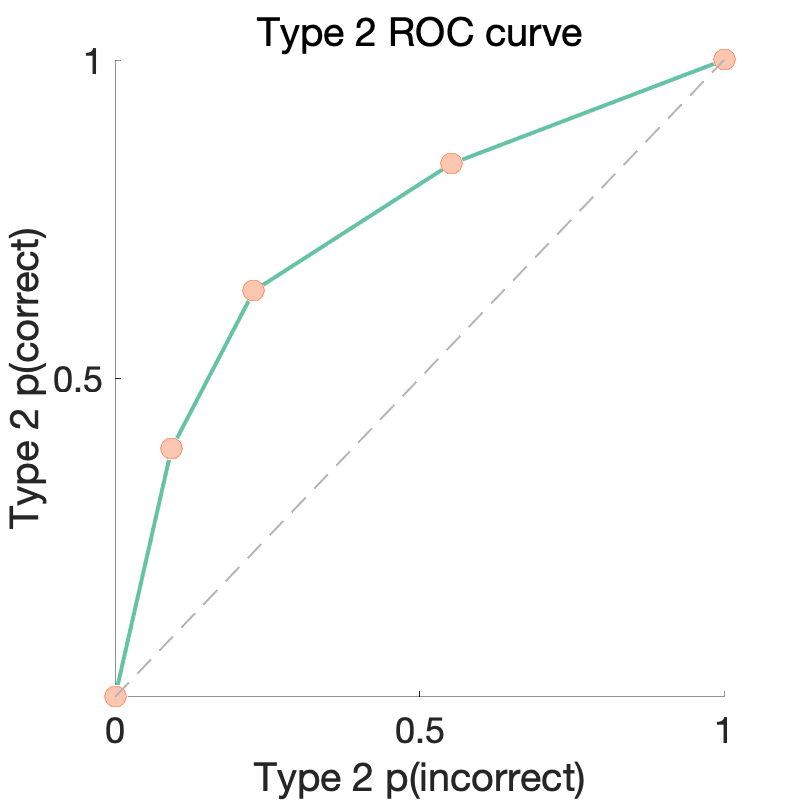

% Get 'response S1' & 'response S2'
% metaCountsAll(:,:,thisSub) = [nR_S1; nR_S2];
clear nR_S1 nR_S2 
nR_S1 = metaCountsAll(1,:,:);
nR_S2 = metaCountsAll(2,:,:);

nR_S1_mean  = mean(nR_S1,3);
nR_S2_mean  = mean(nR_S2,3);

rocData.nR_S1     = nR_S1_mean;
rocData.nR_S2     = nR_S2_mean;

% Find incorrect observed ratings...
I_nR_rS2 = rocData.nR_S1(nRatings+1:end);
I_nR_rS1 = rocData.nR_S2(nRatings:-1:1);
I_nR = I_nR_rS2 + I_nR_rS1;
% Find correct observed ratings...
C_nR_rS2 = rocData.nR_S2(nRatings+1:end);
C_nR_rS1 = rocData.nR_S1(nRatings:-1:1);
C_nR = C_nR_rS2 + C_nR_rS1;
% Calculate type 2 hits and false alarms
for i = 1:nRatings
    obs_FAR2_rS2(i) = sum( I_nR_rS2(i:end) ) / sum(I_nR_rS2);
    obs_HR2_rS2(i)  = sum( C_nR_rS2(i:end) ) / sum(C_nR_rS2);
    obs_FAR2_rS1(i) = sum( I_nR_rS1(i:end) ) / sum(I_nR_rS1);
    obs_HR2_rS1(i)  = sum( C_nR_rS1(i:end) ) / sum(C_nR_rS1);
    obs_FAR2(i) = sum( I_nR(i:end) ) / sum(I_nR);
    obs_HR2(i)  = sum( C_nR(i:end) ) / sum(C_nR);
end
obs_FAR2(nRatings+1) = 0;
obs_HR2(nRatings+1)  = 0;

% Set up figure
fig_position    = [200,200,400,400];        % square
f8  = figure('Position', fig_position);
title(['Type 2 ROC curve'],'fontsize',fontSize+2,'FontWeight','Normal');
set(gcf,'color','w'); hold on

plot(obs_FAR2, obs_HR2, 'o-','Color',cl(1,:),'MarkerSize',10,'LineWidth',lineWidth+1,'MarkerEdgeColor',[1 1 1],'MarkerFaceColor',[1 1 1]);
hold on
scatter(obs_FAR2, obs_HR2,scatterMarkerSize*3,'MarkerEdgeColor', cl(2,:),'MarkerFaceColor',cl(2,:),'MarkerFaceAlpha', .5);
h4              = refline(1);
h4.Color        = cl(3,:);
h4.LineStyle    = '--';
h4.LineWidth    = lineWidth;
h4.HandleVisibility ='off';

set(gca,'fontsize',fontSize,'FontName',fontName) 
xticks([0,.5, 1]);
yticks([.5, 1]);
% hold on
% legend('Observed','Location','SouthEast','fontsize',fontSize);
% legend boxoff 
ylabel('Type 2 p(correct)');
xlabel('Type 2 p(incorrect)');

## Subject-level analyses

%% Select a file & load
fPath           = '../../data/RRST_SubLevelData_15-Apr-2021_12-59.csv';
data            = readtable(fPath);
markerSize  = 20;

Get out some variables

subNo       = unique(data(:,1));
psidata     = data(:,1:7);
questdata   = data(:,[1,8:13]);
corrData    = data(:,[2:4,8,10,27]);               % Data for correlation plot

% --------- CURRENT -------------------
% 1     subject ID
% 2:7   Psi data, (thresh, slope, acc, dizzy, breathless, asthma)
% 8:13  Quest data, (thresh, slope, acc, dizzy, breathless, asthma)
% 14:25 Unpleasantness ratings
% 26:29 google spreadsheet data (google ID, staircase order, age, sex)
%
%       {'ID' 'psi_thresh' 'psi_slope' 'psi_acc' 'psi_dizzy' 'psi_breathless' 'psi_asthma',...
%     'quest_thresh' 'quest_slope' 'quest_acc' 'quest_dizzy' 'quest_breathless' 'quest_asthma',...
%     'displeasure1' 'displeasure2' 'displeasure3' 'displeasure4' 'displeasure5' 'displeasure6',... 
%     'displeasure7' 'displeasure8' 'displeasure9' 'displeasure10' 'displeasure11' 'displeasure12',... 
%     'gID' 'order' 'age' 'sex'}; 

A. Threshold correlation between stairacse procedures

fig_position    = [200,200,415,400];
f2     = figure('Position', fig_position);
set(gcf,'color','w');


clear xVal yVal

% Get threshold data
xVal  	= data.psi_thresh;
yVal   	= data.quest_thresh;

% Fit 1st degree polynomial
[p,S]   = polyfit(xVal,yVal,1); 
% Evaluate the first-degree polynomial fit in p at the points in x. 
%Specify the error estimation structure as the third input so that polyval 
%calculates an estimate of the standard error. The standard error estimate is returned in delta.
[y_fit,delta] = polyval(p,xVal,S);

% Set colours & plot data points
col     = cl(2,:);      
% Could colour by gender, session order, age, etc
% col     = linspace(1,30,height(subNo));
scatter(xVal,yVal,markerSize+180,col,'filled', 'MarkerEdgeColor',col,'MarkerFaceAlpha', .5,'LineWidth',1);
hold on

% Ploynomial fit
plot(xVal,y_fit,'-','Color',cl(1,:),'LineWidth',lineWidth+1)
% Plot 95% CIs (but as lines)
% plot(xVal,y_fit+2*delta,'-','Color',cl(3,:),'LineWidth',lineWidth-1)
% plot(xVal,y_fit-2*delta,'-','Color',cl(3,:),'LineWidth',lineWidth-1)

% Edit figure properties
title(['Reliability'],'fontsize',fontSize+2,'FontWeight','Normal');
axis([8 18.2 8 18.2]);
xticks([3.6, 7.2, 10.8, 14.4, 18]);
xticklabels({'20', '40', '60', '80', '100'});
yticks([3.6, 7.2, 10.8, 14.4, 18]);
yticklabels({'20', '40', '60', '80', '100'});
xlabel('Psi threshold');
ylabel('Quest threshold');
set(gca,'FontName',fontName,'fontsize',fontSize)
grid on

% STATS
% linear correlation (Pearson's b/c continuous data)
disp(['Pearson correlation between staircase threhsolds results: ']);

Pearson correlation between staircase threhsolds results: 


clear corr
[rhoP,pvalP] = corr(xVal,yVal)

rhoP = 0.8780

pvalP = 4.0889e-11

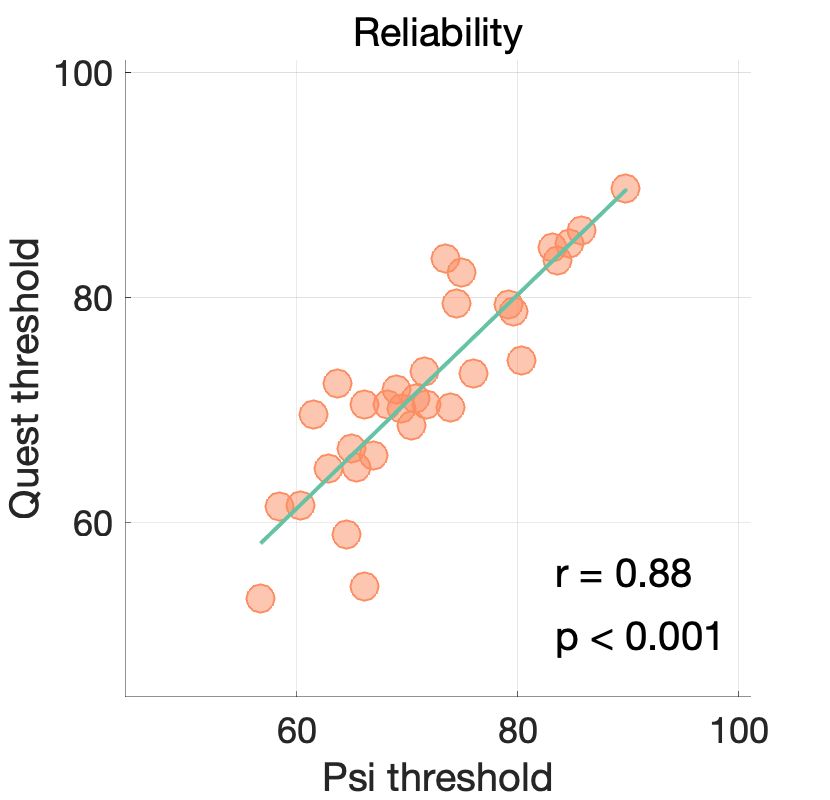


% % Stats, linear correlation (Spearman for comparison)
% disp(['Spearman rank-order correlation between staircase threhsolds results: ']);
% [rhoS,pvalS] = corr(xVal,yVal,'type','Spearman')
% 
% Show r and p on plot
txtr     = ['r = ', sprintf('%.2f', rhoP)];
text(15,10,txtr,'FontName',fontName,'fontsize',fontSize+2)
if pvalP < 0.001
    txtp     = ['p < 0.001'];
else
    txtp     = ['p = ', sprintf('%.2f', pvalP)];
end
text(15,9,txtp,'FontName',fontName,'fontsize',fontSize+2)

### Task unpleasantness



displ       = table2array(data(:, 14:23));
displmeans  = nanmean(displ);
displmedians = nanmedian(displ);
nRatings    = size(displ,2);
X           = categorical(1:nRatings);

SEM = nanstd(displ)/sqrt(size(displ,2));                % Standard Error of mean

% Scatter of raw data points
scatxVals = repmat(X,size(displ,1),1);


## Task unpleasantness as ribbon plot

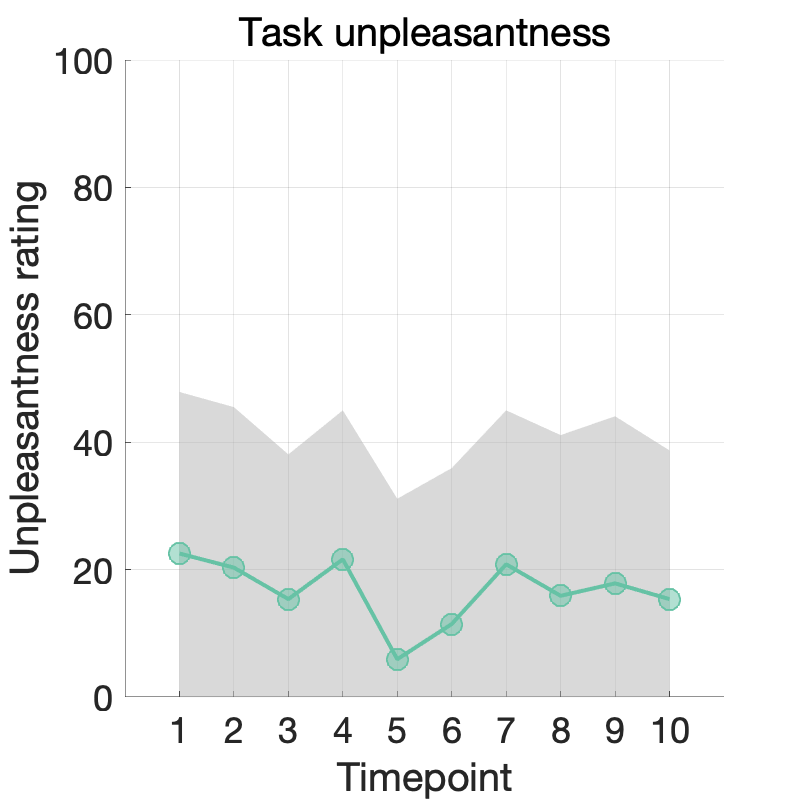

fig_position    = [200,200,400,400];
f6     = figure('Position', fig_position);
set(gcf,'color','w');
hold on;

clear upper lower
displmeans; 
displmedians;
nRatings;
X;

SEM;                % Standard Error of mean

% Plot scatter of raw data points
scatxVals;

% Calculate 95% CIs
N = size(displ,1);
CI95    = tinv([0.025 0.975], N-1);       	% Calculate 95% Probability Intervals Of t-Distribution
yCI95   = bsxfun(@times, SEM, CI95(:));   	% Calculate 95% Confidence Intervals Of All Experiments At Each Value Of ?x?

% Calculate inter-quartile range (IQR) for median error bars
for cols = 1:size(displ,2)
    pd = fitdist(displ(:,cols),'Normal');
    y = icdf(pd,[0.25,0.75]);
    lower(cols) = displmedians(cols)-y(1);
    upper(cols) = y(2)-displmedians(cols);
end
displIqr = iqr(displ);

halfIqr = displIqr/2;
lower = displmedians - halfIqr;
upper = displmedians + halfIqr;

% Plot error range
ciplot(lower,upper,[1:nRatings],cl(3,:));         % Plot 95% CI as filled area
hold on
plot(1:nRatings, displmedians,'-','Color',cl(1,:),'LineWidth',lineWidth+1);    % Add mean line
scatter(1:nRatings,displmedians,markerSize+100,cl(1,:),'filled','MarkerEdgeColor',cl(1,:),'MarkerFaceAlpha',.5,'LineWidth',lineWidth);


title(['Task unpleasantness'],'fontsize',fontSize+2,'FontWeight','Normal');
ylabel('Unpleasantness rating');
xlabel('Timepoint');
axis([0 11 0 100]);
xticks(1:nRatings);
% xticklabels({'0', '50', '100', ''});
set(gca,'FontName',fontName,'fontsize',fontSize)
grid on

Subjective ratings bar plot

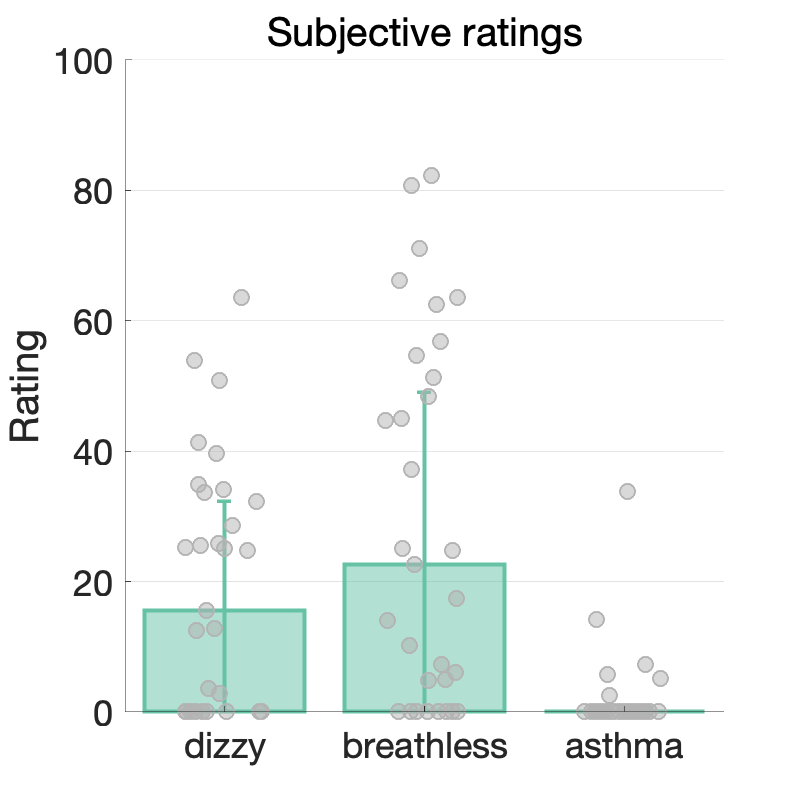

markerSize      = 60;
fig_position    = [200,200,400,400];
f8              = figure('Position', fig_position);
set(gcf,'color','w');

xVals   = categorical({'dizzy', 'breathless', 'asthma symptoms'});
xVals   = reordercats(xVals,{'dizzy', 'breathless', 'asthma symptoms'});
ratings = horzcat(data.psi_breathless, data.psi_dizzy , data.psi_asthma);
% yVals   = nanmean(ratings);
yVals   = nanmedian(ratings);
% Calculate SEM
SEM = nanstd(ratings)/sqrt(size(ratings,1));   
% Calculate IQR (for median)
displIqr = iqr(ratings)/2;

%halfIqr = displIqr/2;


% Remove asthma
clear xVals
xVals   = categorical({'dizzy', 'breathless','asthma'});
xVals   = reordercats(xVals,{'dizzy', 'breathless', 'asthma'});
yVals   = yVals(1:3);
SEM     = SEM(1:3);

bar(xVals,yVals,'EdgeColor',cb(1,:),'FaceColor',cl(1,:),'FaceAlpha',.5,'LineWidth',lineWidth+1)
hold on
errorbar(xVals,yVals,displIqr,'LineWidth', lineWidth+1,'Color',cl(1,:), 'LineStyle','none')

% Add scatter of raw data points
scatxVals = repmat(xVals,size(ratings,1),1);
s1      = scatter(scatxVals(:,1), ratings(:,1),markerSize,cl(3,:),'filled','jitter','on', 'jitterAmount', .2,'MarkerEdgeColor',cl(3,:),'MarkerFaceAlpha',.5,'LineWidth',1);
s2    	= scatter(scatxVals(:,2), ratings(:,2),markerSize,cl(3,:),'filled', 'jitter','on', 'jitterAmount', .2,'MarkerEdgeColor',cl(3,:),'MarkerFaceAlpha',.5,'LineWidth',1);
s3     	= scatter(scatxVals(:,3), ratings(:,3),markerSize,cl(3,:),'filled', 'jitter','on', 'jitterAmount', .2,'MarkerEdgeColor',cl(3,:),'MarkerFaceAlpha',.5,'LineWidth',1);

% Edit figure properties
title(['Subjective ratings'],'fontsize',fontSize+2,'FontWeight','Normal');
ylim([0 100])
ylabel('Rating');
set(gca,'FontName',fontName,'fontsize',fontSize)
ax = gca;
ax.XGrid = 'off';
ax.YGrid = 'on';
box off

## Constant flow physio measures

%% Select a file & load
fPath           = '../../data/NZ_constant_flow_rrst.csv';
data            = csvread(fPath);
data            = data(1:17,1:6);


nSteps = size(data,1);
percentObstruction = ([1:nSteps]*5.5556)';

Set up figure & plot resistance by obstruction 

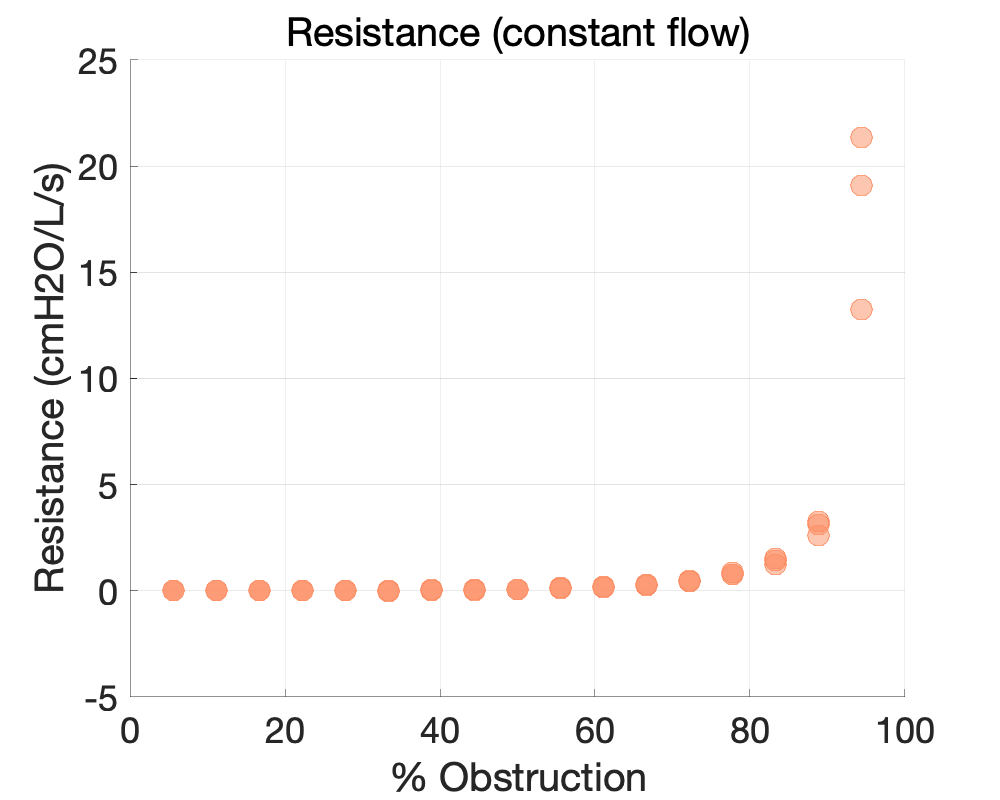

fig_position    = [200,200,500,400];
f6     = figure('Position', fig_position);
set(gcf,'color','w');
hold on;
% Plot resistance for constant airflow
for i = 1:3
    scatter(percentObstruction, data(:,i),scatterMarkerSize*3,'MarkerEdgeColor', cl(2,:),'MarkerFaceColor',cl(2,:),'MarkerFaceAlpha', .5);
end
% Format figure
title(['Resistance (constant flow)'],'fontsize',fontSize+2,'FontWeight','Normal');
ylabel('Resistance (cmH2O/L/s)');
xlabel('% Obstruction');
set(gca,'FontName',fontName,'fontsize',fontSize)
grid on

Plot ln(resistance)

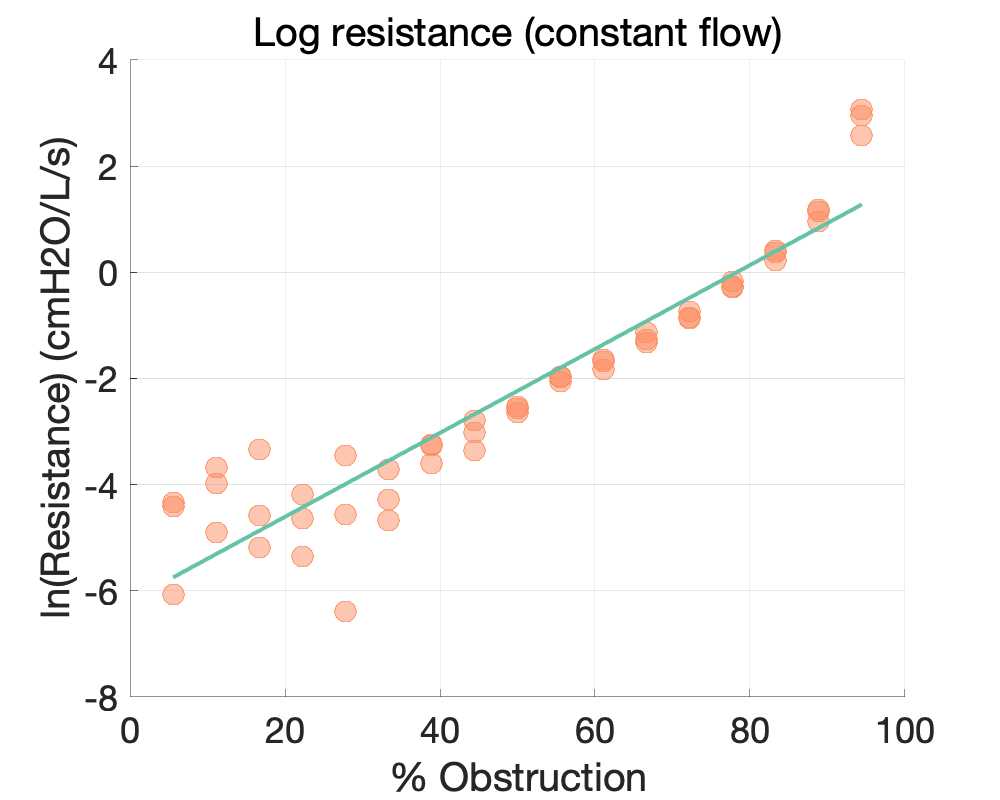

fig_position    = [200,200,500,400];
f6     = figure('Position', fig_position);
set(gcf,'color','w');
hold on;
for i = 4:6
    scatter(percentObstruction, data(:,i),scatterMarkerSize*3,'MarkerEdgeColor', cl(2,:),'MarkerFaceColor',cl(2,:),'MarkerFaceAlpha', .5);
end

% Fit 1st degree polynomial
xVal = [percentObstruction; percentObstruction; percentObstruction];
yVal = [data(:,4);data(:,5);data(:,6)];
regressMat = [xVal, yVal];
regressMatSorted = sortrows(regressMat,1);

[p,S]   = polyfit(regressMatSorted(:,1),regressMatSorted(:,2),1); 
% Evaluate the first-degree polynomial fit in p at the points in x. 
%Specify the error estimation structure as the third input so that polyval 
%calculates an estimate of the standard error. The standard error estimate is returned in delta.
[y_fit,delta] = polyval(p,regressMatSorted(:,1),S);

% Set colours & plot data points
col     = cl(2,:);      
% Ploynomial fit
plot(regressMatSorted(:,1),y_fit,'-','Color',cl(1,:),'LineWidth',lineWidth+1)


% Format figure
title(['Log resistance (constant flow)'],'fontsize',fontSize+2,'FontWeight','Normal');
ylabel('ln(Resistance) (cmH2O/L/s)');
xlabel('% Obstruction');
set(gca,'FontName',fontName,'fontsize',fontSize)
grid on

% Stats
[rhoP,pvalP] = corr(regressMatSorted(:,1),regressMatSorted(:,2))

rhoP = 0.9405

pvalP = 1.2813e-24

## Physio measures

%% Select a file & load
fPath           = '../../data/NZrrstResistance.csv';
data            = readtable(fPath);

dataArray = table2array(data);

% Extract variables
subNo       = unique(dataArray(:,1));
step        = dataArray(:,2);
resistance   = dataArray(:,3);
pressure    = dataArray(:,4);
resistanceLn = dataArray(:,5);
pressureLn   = dataArray(:,6);

nSteps = max(step);
stepObstruction = step * 5.5556;

subMeans = [];

Get mean for each participant

counter = 1;
for i = 1: size(subNo,1)
    sID = subNo(i);
    subData = dataArray((dataArray(:,1)==sID),:);
    stimLevels = unique(subData(:,2));
    
    for j = 1: size(stimLevels,1)
        
        stim = stimLevels(j);
        
        resistLnStim = subData((subData(:,2)==stim),5);
        resistSubMean = nanmean(resistLnStim);
        
        pressLnStim = subData((subData(:,2)==stim),6);
        presssSubMean = nanmean(pressLnStim);
        
        subMeans(counter,1) = sID;
        subMeans(counter,2) = stim;
        subMeans(counter,3) = resistSubMean;
        subMeans(counter,4) = presssSubMean;
        
        counter = counter+1;
    end
    
end


subMeans(:,2) = subMeans(:,2)*5.5556; % Multiply to tranform step size into % obstruction

Set up figure and plot

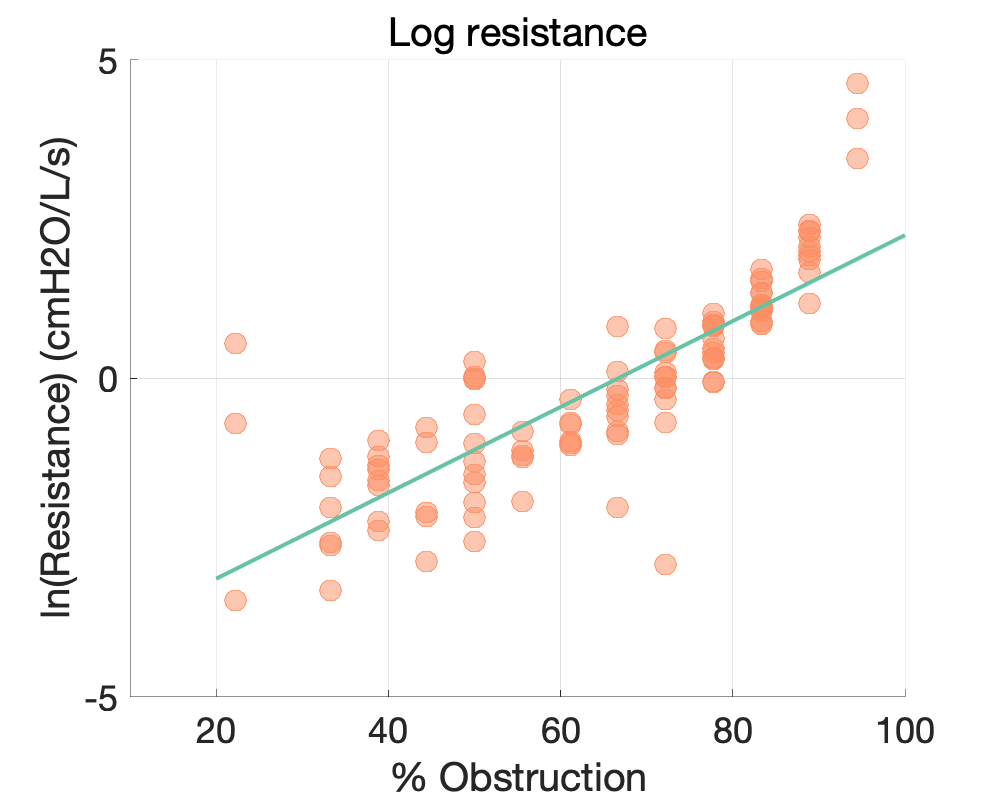

fig_position    = [200,200,500,400];
f6     = figure('Position', fig_position);
set(gcf,'color','w');
hold on;

%scatter(stepObstruction, resistanceLn, scatterMarkerSize*3,'MarkerEdgeColor', cl(2,:),'MarkerFaceColor',cl(2,:),'MarkerFaceAlpha', .5);
scatter(subMeans(:,2), subMeans(:,3), scatterMarkerSize*3,'MarkerEdgeColor', cl(2,:),'MarkerFaceColor',cl(2,:),'MarkerFaceAlpha', .5);
h1 = lsline;
h1.Color = cl(1,:);
h1.LineWidth = lineWidth+1;
clear h1

% Format figure
title(['Log resistance'],'fontsize',fontSize+2,'FontWeight','Normal');
ylabel('ln(Resistance) (cmH2O/L/s)');
xlabel('% Obstruction');
set(gca,'FontName',fontName,'fontsize',fontSize)
axis([10 100 -5 5]);
grid on

% Stats
subMeansSorted = sortrows(subMeans,2);
subMeansSorted(any(isnan(subMeansSorted), 2), :) = [];          % delete rows containing NaNs
[rhoP,pvalP] = corr(subMeansSorted(:,2),subMeansSorted(:,3))

rhoP = 0.8207

pvalP = 8.6990e-27

Plot ln(pressure)

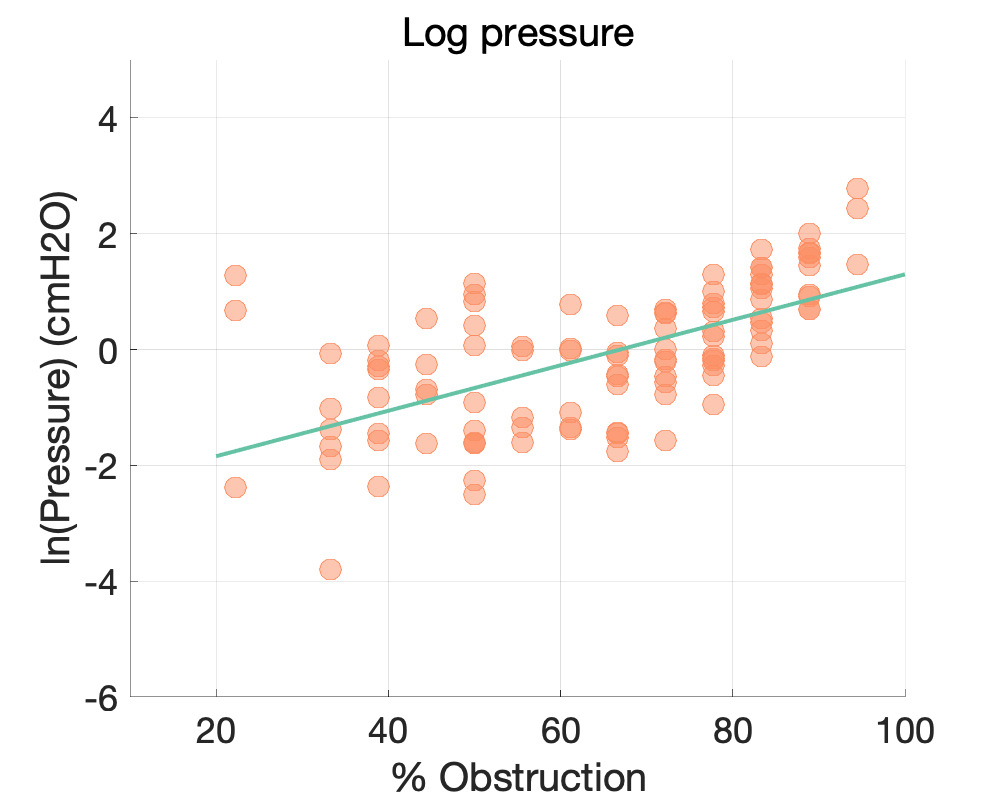

fig_position    = [200,200,500,400];
f6     = figure('Position', fig_position);
set(gcf,'color','w');
hold on;

%scatter(stepObstruction, pressureLn, scatterMarkerSize*3,'MarkerEdgeColor', cl(2,:),'MarkerFaceColor',cl(2,:),'MarkerFaceAlpha', .5);
scatter(subMeans(:,2), subMeans(:,4), scatterMarkerSize*3,'MarkerEdgeColor', cl(2,:),'MarkerFaceColor',cl(2,:),'MarkerFaceAlpha', .5);
h1 = lsline;
h1.Color = cl(1,:);
h1.LineWidth = lineWidth+1;
clear h1

% Format figure
title(['Log pressure'],'fontsize',fontSize+2,'FontWeight','Normal');
ylabel('ln(Pressure) (cmH2O)');
xlabel('% Obstruction');
set(gca,'FontName',fontName,'fontsize',fontSize)
axis([10 100 -6 5]);
grid on

% Stats
[rhoP,pvalP] = corr(subMeansSorted(:,2),subMeansSorted(:,4))

rhoP = 0.6163

pvalP = 2.5743e-12


% Clean up
clear data resistance pressure resistanceLn pressureLn percentObstruction

### Comparison between FDT and RRST

Confidence ratings

%% Select a file & load
fPath           = '../../data/NZfdtRrstConfidence.csv';
data            = readtable(fPath);

% Extract variables
fdtConfidence       = table2array(data(:,1));
rrstConfidence      = table2array(data(:,2));



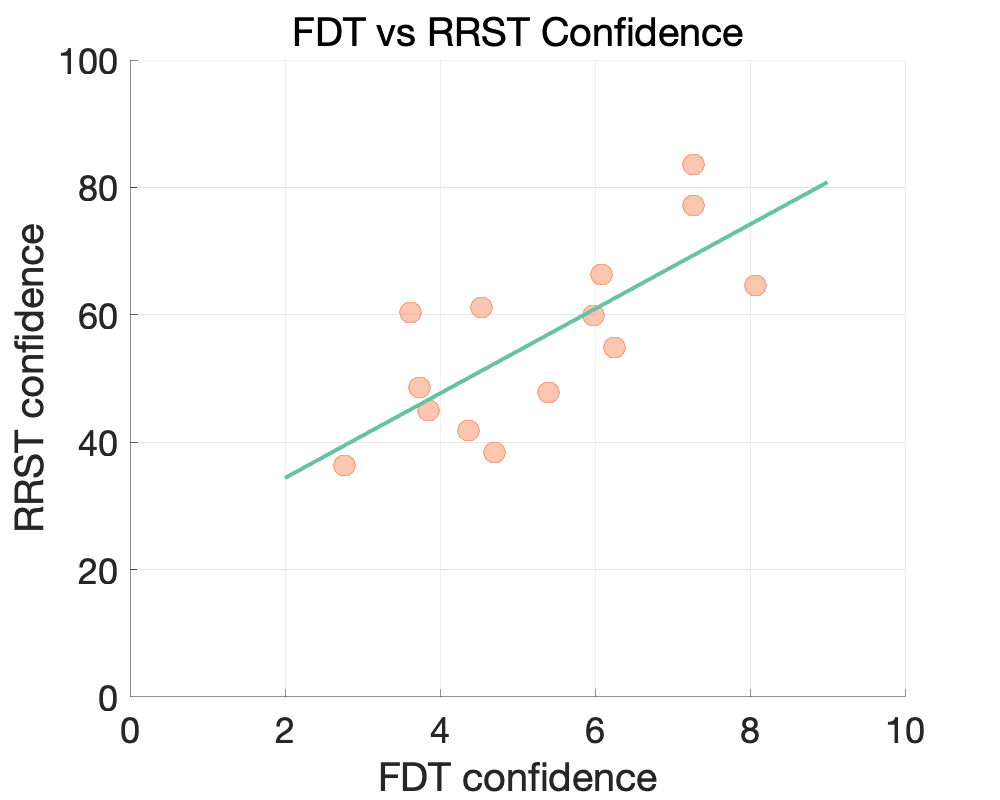

fig_position    = [200,200,500,400];
figure('Position', fig_position);
set(gcf,'color','w');
hold on;

scatter(fdtConfidence, rrstConfidence, scatterMarkerSize*3,'MarkerEdgeColor', cl(2,:),'MarkerFaceColor',cl(2,:),'MarkerFaceAlpha', .5);
h1 = lsline;
h1.Color = cl(1,:);
h1.LineWidth = lineWidth+1;
clear h1

% Format figure
title(['FDT vs RRST Confidence'],'fontsize',fontSize+2,'FontWeight','Normal');
ylabel('RRST confidence');
xlabel('FDT confidence');
set(gca,'FontName',fontName,'fontsize',fontSize)
axis([0 10 0 100]);
grid on

Accuracy

%% Select a file & load
fPath           = '../../data/NZfdtRrstAccuracy.csv';
data            = readtable(fPath);

% Extract variables
fdtAccuracy       = table2array(data(:,1));
rrstAccuracy      = table2array(data(:,2));



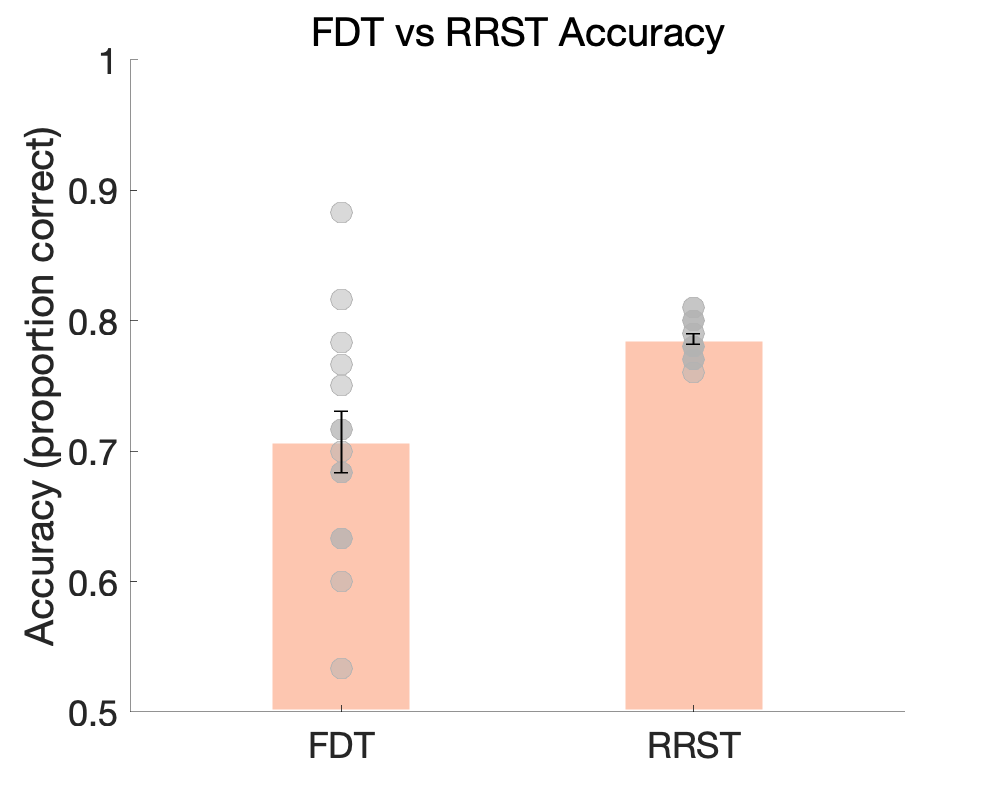

fig_position    = [200,200,500,400];
figure('Position', fig_position);
set(gcf,'color','w');
hold on;

%boxplot([fdtAccuracy, rrstAccuracy],'Colors',cl(1,:))

fdt_SEM = nanstd(fdtAccuracy)/sqrt(size(fdtAccuracy,1)); 
rrst_SEM = nanstd(rrstAccuracy)/sqrt(size(rrstAccuracy,1)); 
bar([1,1.5], [nanmean(fdtAccuracy), nanmean(rrstAccuracy)],0.4,'EdgeColor',[1 1 1],'FaceColor',cl(2,:),'FaceAlpha',.5,'LineWidth',lineWidth+1);
hold on

scatter(ones(size(fdtAccuracy)), fdtAccuracy, scatterMarkerSize*3,'MarkerEdgeColor', cl(3,:),'MarkerFaceColor',cl(3,:),'MarkerFaceAlpha', .5);
scatter(1.5*ones(size(rrstAccuracy)), rrstAccuracy, scatterMarkerSize*3,'MarkerEdgeColor', cl(3,:),'MarkerFaceColor',cl(3,:),'MarkerFaceAlpha', .5);

er = errorbar([1,1.5], [nanmean(fdtAccuracy), nanmean(rrstAccuracy)], [fdt_SEM, rrst_SEM],'HandleVisibility','off');    
er.Color = [0 0 0];                            
er.LineStyle = 'none';
er.LineWidth = lineWidth;

% Format figure
title(['FDT vs RRST Accuracy'],'fontsize',fontSize+2,'FontWeight','Normal');
ylabel('Accuracy (proportion correct)');
set(gca,'FontName',fontName,'fontsize',fontSize)
axis([0.7 1.8 0.5 1]);


% Edit figure properties
xticks([1, 1.5]);
xticklabels({'FDT', 'RRST'});

set(gca,'fontsize',fontSize,'FontName',fontName) 
set(gca,'Layer','top')